# Geoscience Data Analysis

*D. Hasterok (derrick.hasterok@adelaide.edu.au)*

*Dept. of Earth Sciences, University of Adelaide, North Terrace, Adelaide, SA 5005*

## Preface

This text is an overview of a broad range of data analysis techniques that are useful to Earth Scientists studying in a variety of subdisciplines.  I have used a surprising number of these techniques in my own work and hopefully you will find them applicable to your work as well.  Unfortunately, the set of techniques are too broad to cover all the intricacies of each one in this text.  

In this data analysis course, I have chosen to write as much of the notes in a set of MATLAB live scripts as opposed to a traditional static document for a few key reasons.  First and foremost, this course is one in which you will be learning to program some simple data analysis for yourselves.  A live script allows me to insert code directly into the document that generates the figures in the document.  This ability will help you understand how you can do something similar.  You will also see how easy it can be to write code without much experience.  One thing you will have to learn is what functions are available and how to use them and these documents will provide many concrete examples.  Second, a static example is only so useful if you don't know how to connect the math with what happens to a curve or points on a figure.  The live script is just that, live.  You can change the code and see what happens.  Break it, fix it, and change the inputs.  You'll develop intuition by doing so and probably learn it faster in the process.  If you ever happen to break it and find you just can't fix it, just download a clean copy and try again.  Never be afraid to break a computer code.  Unlike all the other work you do, there is a near zero cost to breaking a code, all you waste is a little time and a few electrons.

I have example code for many of the techniques discussed in the course.  Although MATLAB toolboxes have many of these techniques available to use as functions, when the method is fairly straightforward, I may not use the toolbox version, so that you have a better idea of what the code is doing.  It also may be that non-standard toolboxes are not installed by default so having the longer form will help you compute the necessary quantities for yourself.  It also makes the example somewhat more applicable to other computer languages other than MATLAB, which also may not have functions for the various techniques.

In order to analyze data, you will need to do some math and understand even more conceptually.  Your math backgrounds probably vary considerably, some of you may have sought math courses out while others avoided it at all costs.  Be aware that your apprehensiveness about math is less about your ability to do so than perhaps the perception that math is difficult.  It isn't necessarily any more difficult than learning any other skill, it just requires more thought and less physical labor, and you probably had poor teachers and people telling you it was hard all your life until you believed it yourself.  Unfortunately, in this course there isn't the time to cover all of the background you might need, but I have a another set of notes that you can look through as a refresher or as quick reference guide.  In this course we will use a number of math symbols that you may not be familiar with.  If you don't recognize one, ask during or after class.  I guarantee if you don't know it, you likely are not the only one and the whole class will benefit if you just ask...you'll also get a bunch of people congratulating you later for asking because they might have been too scared or embarrassed to do so.  I won't think lesser of you.  Though if you are uncomfortable, you can write me an anonymous note and I'll cover it before the next lesson.

That said, I will mention a few concepts here as they will be used some as they are needed in the course.  There will be limited calculus (integrals and derivatives), though mostly, we will be working with sums and differences and some linear algebra (matrix math).  In general, the heavy lifting will be handled by the computer.  Let's start with a few simple symbols:

$\sum$ is used to denote a sum.  We will add annotations to tell us where to start and where to end the sum, i.e., $\sum_{i=1}^N$ tells us that we start at 1 and end at N.  The variable $i$ is an index variable, which we typically use as a subscript to denote a variable that changes with each term in the sum.  For each term in the sum, $i$ will increase by a unit of 1. For example, if $x = \{1, 2, 3, 4\}$,


$$\sum_{i = 1}^4 2 x_i = (2 \cdot 1) + (2 \cdot 2) + (2 \cdot 3) + (2 \cdot 4) = 20$$


We will also use a symbol $\prod$ to indicate a multiplication of terms in a similar way as we used $\sum$ to indicate a sum, i.e.,


$$\prod_{i=1}^4 x_i = 1 \cdot 2 \cdot 3 \cdot 4 = 24$$


Note that in probability and statistics, a product of integers from 1 to some value $n$ is very common.  In this case, we call this the factorial function and indicate it with an exclamation point, i.e., $n! = \prod_{i=1}^n i$ .

Another symbol we will use is the Greek letter delta, which we will use to indicate a difference between two values.  For most differences, we use the capital form, $\Delta$, and for small differences, we use a $\delta$, but for infinitesimally small differences, we use a $d$ or a stylized d, $\partial$.  For example, for a difference between two $x$ values, $x_{i}$ and $x_{i+1}$, we would write, $\Delta x = x_{i+1} - x_i$ .  You can also think of this difference as a step size, i.e., starting at $x_i$ and taking a step $\Delta x$, we arrive at $x_{i+1}$ or rather, $x_{i+1} = x_i + \Delta x$.

The calculus you will need and/or use in this course is minimal, but it is helpful to know what the symbols mean because they come up not infrequently in scientific texts.  The derivative is simply the slope of a function at a given point.  For a given function, $F(x)$, the slope at a point $x$, can be approximated by the change in the function divided by the step size (rise over run),


$$f(x) \approx \frac{F(x+\Delta x) - F(x)}{(x + \Delta x) - x}$$


which is simply, 

$f(x) \approx \frac{F(x+\Delta x) - F(x)}{\Delta x}$. 

If our $\Delta x$ gets small, $\delta x$, then in the limit that $\delta x$ approaches 0, the slope becomes the derivative, $f(x)$, a function in its own right,


$$f(x) = \lim_{\delta \to 0} \frac{F(x + \delta x)}{\delta x} = \frac{dF}{dx}$$


We don't normally go through the long form to derive every fundamental derivative; we just look up the basic form in a book and do a few creative substitutions to find the derivative for our application.  Most can be done fairly simply, though it can take a little practice.  Fortunately, the website [https://www.wolframalpha.com/](https://www.wolframalpha.com/) is a convenient resource.  For additional information and a more visual description, see the additional math notes.

Generally, when you see $\partial F/\partial x$ instead of $dF/dx$ it is because there are multiple dimensions that one could take the derivative with respect to.

The integral is the opposite of a derivative or anti-derivative.  Rather than a difference, an integral is a sum.  Rather than the slope of a function, the integral is an area between a function and a zero line.  We can write an approximated version as a sum of $n$ rectangles over a range from point $a$ to $b$, each with width, $\Delta x$,


$$F(x) \approx \sum_{i = 1}^n f(x_{i}) \Delta x$$


where $a \leq x_1 < x_2 < ... < x_i < ... < x_n \leq  b$, again, if we take the limit as $n$ approaches an infinite number of divisions, then $\Delta x$ becomes infinitesimally small, i.e.,


$$\lim_{n \to \infty} \sum_{i = 1}^n f(x_i) \delta x = \int_a^b f(x)\, dx$$


This result is known as a definite integral because the limits of integration $a$ and $b$ are specified.  Sometimes you may see an integral written without the limits $a$ and $b$.  In those cases, the form is known as an indefinite integral.  Don't worry about that particular distinction too much.  Just like derivatives, we often look up the form of an integral that we need and use substitutions to get it into the form we need.  For additional information and a more visual description I refer you to the math notes, and to solve one, you can frequently use the website [https://www.wolframalpha.com/](https://www.wolframalpha.com/) without having to do much of the heavy lifting.

## Additional Resources

These notes are not the only place you can get information about these topics as you study in this course.  There are a lot of free resources available on the web, some quite good.

Alan Chave's 2017 textbook, Computational Statistics in the Earth Sciences: With Applications in MATLAB published by Cambridge ISBN: 9781316156100, doi: [https://doi.org/10.1017/9781316156100](https://doi.org/10.1017/9781316156100).  The university has a subscription.

Wolfram Alpha ([https://www.wolframalpha.com/](https://www.wolframalpha.com/)) a mostly-free computational engine online.  It can do symbolic math (integrals and derivatives) and show you the steps.  For example, try "integrate a*sin(2*pi*x) dx from 0 to pi/2" and see what you get.

Wikipedia is actually a pretty good resource for math related topics, though it is generally written for someone who has a basic knowledge of the subject in question, which may be frustrating if you are trying to learn about a topic from zero.  That said, I've found techniques that I didn't realize existed that have become super useful in the course of my own research (e.g., rejection sampling).

Khan Academy is a good resource with videos.  The concepts are typically taught in a basic enough manner to move to a more intermediate level of understanding.

Minitab Blog covers a lot of standard statistical topics without a lot of math.  They sell statistical software, but they want you to know how it works even if you can't write the codes to do it yourself.

% allow MATLAB to look for additional functions in a directory called codes
addpath ../codes

# 1 Distributions and Sampling

## 1.1 Introduction

The basics of data analysis begin with the concepts of probability distributions.  When we take a measurement, there is an inherent uncertainty associated with the measurement.  These uncertainties could be instrumental, environmental, or the result of processes that we cannot control that creates a natural variability.  Instrumental uncertainties happen as a result of the measurement itself, which can arise from any number of factors (e.g., instrumental drift, threshold quantities for detection, minimum detectible differences, measurement discretization).  These effects are often referred to as instrumental noise, some of which can be partially corrected (i.e., drift corrections) or reduced by collecting replicates (we'll discuss replication).  Natural variability can be introduced by incomplete mixing of sources, variations in environmental conditions, kinetic effects, alteration, etc.  Natural variability is particularly concerning when it creates trends that are not part of the desired signal, or noise that obscures a process.  At a fundamental level the description of uncertainties from each of these processes share a common language.

It is not uncommon for uncertainties to be called errors, instrument or measurement error.  Often, we call uncertainties added on data in plots error bars.  Although, in neither case are these necessarily errors with the implication that something went wrong.  Often these are the result of machine or scale precision that are rounded up or down, but the process is typically random and therefore an uncertainty on multiple measurements. I never use the term errors in my papers because of the implication that something went wrong and I want to emphasize that to the reader, especially a lay reader that may not understand the way in which most scientists us the term error. (Assuming a lay person ever reads one of my papers may be a stretch.)

## 1.2 Definitions

Language is messy.  When we talk, we are often at our sloppiest because we don't often stop to think about the optimal word choice to convey an idea. Additionally, we can use the same word, but each person can conceptualize the meaning differently.  To this end, we need to create a precise definition for many of the words you will be exposed to in this course.

### 1.2.1 Data

***Sample*** represents a single unit for analysis, e.g., a hand sample.

***Sample set*** includes a collection of samples (note statisticians often refer to a collection as a sample, e.g., a number of hand samples.  To refer to a single value, statisticians will refer to a sampling unit).

***Subset*** is a subsampling of the sample set, e.g., samples from Australia, only granitic samples, and/or samples from 1.2 to 1.0 Ga.

***Population*** includes the global set of samples, i.e., every possible sample.

***Dimension*** is a quantitative attribute or characteristic of a sample, e.g., location, rock type, SiO2, U, Th.

***Metric*** a measure of distance—not necessarily physical—between two points in a dimension, e.g., concentration in ppm.

***Variable*** is the value of a dimension for a sample.

***Multivariate / multidimensional*** refers to samples that have multiple unique dimensions, e.g., major and trace element analyses.

***Metadata*** are dimensions that describe a sample, sometimes metadata is referred to as data that describes other data, e.g., within the global geochemical database, metadata includes country, method of collection, location, rock type, and sample age.  Metadata can be qualitative or quantitative, be derived from the data and/or be used as a dimension for analysis in its own right.

***Independent and identically distributed*** (IID) *random variables*.   Basically, IID means that the result determined for each sample is independent of the previous result and that any set of samples collected should result in the same mean and standard deviation (i.e., identically distributed).  Note this designation does not mean the result cannot be biased, only that the bias must be the same for every sample set.

### 1.2.2 Distributions

***Probability*** is the likelihood that an event or set of events will occur.  We will denote the probability that $x$ occurs as $\text{Pr}[x]$.  Sometimes we will place conditions on the on the probability, for example we would say $\text{Pr}[x|A]$ is the probability that $x$ occurs given the condition $A$ is met.  We will also refer to the probability density function as the probability in many occasions, though they are subtly different in definition though they may yield the same value.

***Probability density function*** (PDF) describes the probability that an outcome will occur for a particular value.  Often these are expressed for continuous variables so we will need to revise our definitions to handle our discretely sampled data.  The probability density can be expressed in terms of the probability that an event $x$ falls between $a$ and $b$,


$$\text{Pr}[a \leq x \leq b](x) = \int_a^b P(x)\ d\!x$$


where $P$ is the probability density function.

***Cumulative density function*** (CDF) is the probability that a randomly sampled variable will occur at a value of equal to or less than x.  The CDF is related to the PDF by


$$C(x) = \int_{\xi}^{x} P(x')\, d\!x'$$


Note the lower bound, $\xi$, of the integral depends upon the bounds of the PDF, e.g., for a normal distribution $\xi \to -\infty$ and for a log-normal distribution $\xi \to 0$.

***Quantile function*** represents the inverse CDF, $C^{-1}$ or $Q(C(x)) = x$.  Such a function is useful for randomly sampling a distribution as we will later see as well as determining confidence levels used in hypothesis testing. 

### 1.2.3 Averages

It is common for one to use the term ***average*** for which I mildly abhor, really only because most who use the term do not define it.  There are technically many averages, the most common is the mean—also a somewhat nebulous term—but it can also refer to the median, mode and middle (range divided by 2) value.  If you do use the term average, please specify before you use it what average will be used.

The ***expectation*** is the expected value (mean) of a PDF for a given random variable $X$, i.e.,


$$E(X) = \sum_i x_iP(X = x_i)$$


***Mean*** is a very common average that describes the expected value of a distribution.  Generally, when we say mean we refer to the arithmetic mean unless otherwise specified; though again, to remove ambiguity, specify which mean is used in the first instance. 

***Arithmetic mean***, for linear distributions,


$$\bar{x}_a = \frac{1}{N}\sum_i^N x_i$$


For many statistical cases we will write the arithmetic mean without the subscript, i.e., $\bar{x}$.

***Geometric mean***, often more useful for log-normal distributions


$$\bar{x}_g = \prod_i^N x_i^{1/N} \: ,$$


which is related to the arithmetic mean by


$$\log \bar{x}_g = \frac{1}{N}\sum_i^N \log x_i \: .$$


***Harmonic mean***, when taking the average of rates, the mean is defined by


$$\bar{x}_h = \left(\frac{1}{N}\sum_i^N x_i^{-1}\right)^{-1} \: .
$$


***Square-root mean***, there are a limited number of properties whose mean behavior is best described by


$$\bar{x}_{sr} = \frac{1}{N}\sum_i^N \sqrt{x_i} \: .$$


Note: as far as averages go, the arithmetic is always largest, followed by the geometric and finally the harmonic.

### 1.2.4 Moments

***Moment*** refers to the mathematical measure for the shape of a function.  We will discuss several moments with respect to PDFs.  The zero-th moment is the total probability (equal to 1), the first moment is the *mean*, the second moment is the *variance*, the third moment is the *skew*, and the fourth moment is the *kurtosis*.

***Mean***, see arithmetic mean above. Note the definition for the mean above is technically the ***sample mean***, which is determined empirically from a set of data.  The true mean is typically represented by the Greek letter mu, $\mu$.  For code examples, see Section 1.2.3 above.

***Median*** represents the value for which half of the values lie below and half above.  The median is the 0.5 quartile.

***Mode*** is the value that occurs with the highest frequency (highest probability).

***Variance*** measures the spread of a distribution relative to the average.  The *uncorrected variance* is defined as


$$\text{Var}_N(x) = s_N^2 = \frac{1}{N}\sum_{i=1}^N (x - \bar{x})^2$$
 

while the *corrected*, *unbiased*, or *sample variance* is defined as


$$\text{Var}(x) = s^2 = \frac{1}{N-1}\sum_{i=1}^N (x - \bar{x})^2$$


Note, the sample variance is larger than the uncorrected variance because of the smaller dividing factor ($N-1$ versus $N$) in the sample variance.  We will use the sample variance unless otherwise specified.  The true variance is generally represented by the Greek letter sigma as $\sigma^2$.

***Standard deviation*** is a bit simpler to conceptualize than the variance because it has the same units of $x$, whatever that happens to be.  The standard deviation is simply the square-root of the variance $s = \sqrt{Var(x)}$, i.e.,


$$s_N = \left[\frac{1}{N}\sum_{i=1}^N (x - \bar{x})^2\right]^{1/2}$$


and the ***sample standard deviation*** is defined as


$$s = \left[\frac{1}{N-1}\sum_{i=1}^N (x - \bar{x})^2\right]^{1/2}$$


which most programs will compute if you call a function called the standard deviation.  Most people really mean the sample standard deviation when they say standard deviation. The true standard deviation is often referred to as $\sigma$.

***Standard error*** is related to the standard deviation, except that it includes an additional normalization,


$$SE = \frac{s}{\sqrt{N}}$$


The standard error represents an uncertainty in the mean value as opposed to the spread of the distribution and is generally computed from the sample standard deviation.  *See *Section 4.2* on natural versus observational variability.*

***Skew*** is a measure of the asymmetry of a distribution.  Negative or left skewness indicates a long tail below the mean and positive or right skewness indicates a long tail on above the mean.  The *sample skew* can be defined as


$$\text{Skew}(x) = \frac{1}{N} \sum_{i = 1}^N \frac{(x - \bar{x})^3}{s^3}$$


***Kurtosis*** is the measure of tailness, which refers to tails that are shorter (lower probability) or long (higher probability) in reference to a given distribution.  The *sample kurtosis* can be defined as


$$\text{Kurt}(x) = \frac{1}{N} \sum_{i = 1}^N \frac{(x - \bar{x})^4}{s^4} - 3$$


***Absolute deviation*** is another measure for the spread of a distribution, which is defined as


$$\text{ADev}(x) = \frac{1}{N}\sum_{i=1}^{N}|x_i - \bar{x}|$$
 

where the vertical bars $|...|$ denote the absolute value.  The advantage of this moment is that it is affected less by outliers than the traditional standard deviation, where the difference is squared to ensure the difference is positive.

### 1.2.5 Observations

***Accuracy*** is when a distribution of observations clusters about the true value.

***Precision*** is when a distribution of observations has a narrow range.

***Reproducibility*** is when multiple sets of observations yield a similar accuracy and precision.

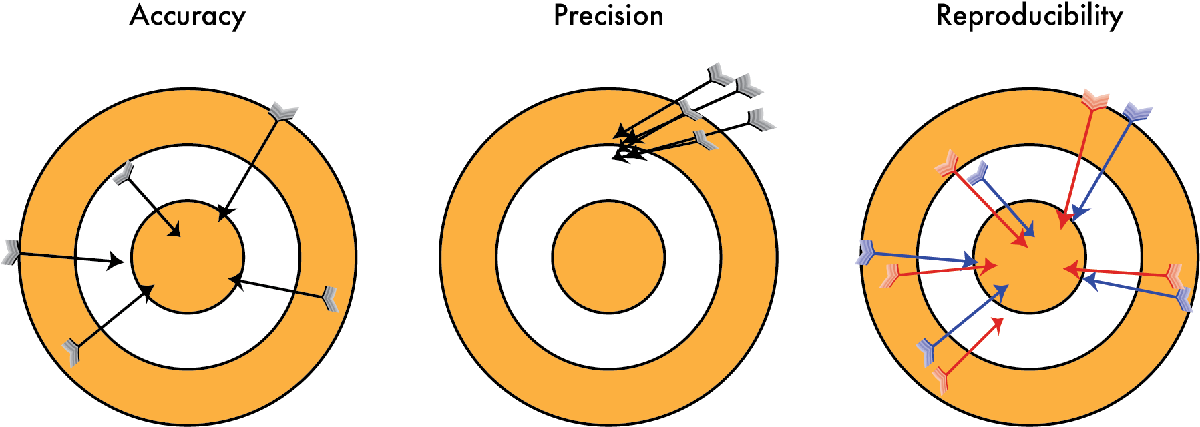

***Figure**** - A demonstration of the differences between accuracy, precision and reproducibility.*

### 1.2.6 Variables types

***Quantitative*** or ***numeric*** are variables that are associated with numbers, they can be continuous or discrete.

***Continuous*** variables have an infinite number of values with no gaps (e.g., temperature, gravity, and mass fraction).  Continuous variables typically have units, though not always.

***Discrete*** variables have gaps—are quantized (e.g., number of sepals, n-alkanes).

***Qualitative*** or categorical variables are not easily quantified but can be differentiated.

***Nominal*** variables are made of categories, but there is no order (e.g., texture, color, and deposit type).  ***Binary*** data are a type of nominal data with only two categories, which can be the presence or absence some observable (a fossil or mineral, etc.).

***Ordinal*** variables are made of categories, but there is an order—as in a typical MATLAB scale on a survey (e.g., conodont alteration index, Mercalli intensity scale, Bouma turbitdite sequence, taxa).

Note that data types are different than observed variables, most observations are measured as a set of discrete samples.

## 1.3 Common Distributions

There are two common distributions that describe uncertainties reasonably well in most cases, the *Gaussian* or *normal distribution* and the *log-normal distribution*.  Another common distribution in Earth science is the *power-law distribution*.

### 1.3.1 Normal Distribution

Given an IID random variable $x$, the probability that a given value of $x \in (-\infty,\infty)$, i.e., $\mathbb{R}$, will be observed is described by the normal probability density function (PDF),

$P(x) = \frac{1}{\sigma\sqrt{2\pi}}\exp\left(-\frac{(x - \mu)^2}{2\sigma^2}\right)$,

where $\mu$ is the mean and $\sigma$ is the standard deviation.  Note $\mu$ and $\sigma$ are also referred to as scale parameters, but rarely for a normal distribution.  The distribution has a characteristic shape, often described as a bell curve as shown below for a $\mu = 0$ and $\sigma=1$.  This mean and standard deviation are different from the sample mean and sample standard deviation determined from the sample set (though they are generally just called mean and standard deviation). Some authors use $\mathcal{N}(x)$ to indicate the normal probability density.

Note, you can change bits of the code to see how things change.  And don't be afraid to break things...it will help you learn; you can always download a clean copy if you can't get it to work again.  Change $\mu$ and $\sigma$ and see how it affects the distribution.  To put in your own values and plot the revised figure type ctrl+enter (windows and linux) or ⌘+enter (mac).

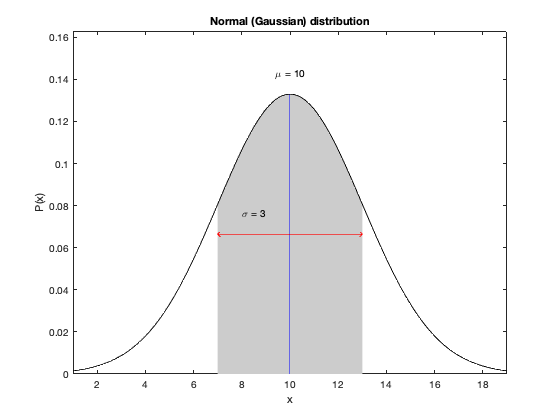

clear all;

% There are a lot of comments (lines that start with %) on in some of these
% snippets of code, I won't always provide this level of detail, but I will
% when I start so that if you have little experience with coding you can
% follow along.  As you see, I will put in PN for programming notes in the
% comments to provide additional information about programming.  Most will
% be specific to MATLAB, but each programming language will have their own
% way of doing something similar.

% make a plot of a Gaussian with scale parameters mu and sigma
mu = 10;       % mean
sigma = 3;    % standard deviation
% PN: A semicolon at the end suppresses output.  If you remove it, you will
% see it print the value placed in the variable.
% PN: the = operator evaluates the expression to the right and assigns it
% to the variable on the left.  It will not work the other way around.
% PN: Variables can have just about any name (no spaces or special characters
% except underscore, '_', are allowed).  MATLAB is case sensitive and while
% it does allow numbers, they may not start a variable name.

% creates a set of values that ranges from -3 to 3 with a step size of 0.02
% if mu and sigma are the default values of 0 and 1, otherwise it adjusts
% the scale factor by the scale parameters.
x = [-3*sigma+mu:0.02*sigma:3*sigma+mu];
% PN: there are at two ways to setup variables in MATLAB. Suppose you want
% to create a variable from a to b with a step size of dx, you write this as
%   x = a:dx:b  (if you leave off a semicolon it will print the result to
%   the screen)
% of if you wanted to create a similar variable, but you wanted N points
% instead of a defined step size
%   x = linspace(a,b,N)

% compute a Gaussian curve for the values stored in the variable x
P = 1/(sigma*sqrt(2*pi)) * exp(-(x - mu).^2/(2*sigma^2));
% PN: ^ means raise to a power.  You might also notice that sometimes a dot
% (.) is used before a math symbol, .*, ./, .^.  There is an important
% difference between * and .*, where * refers to matrix multiplication and
% .* refers to element-wise multiplication.  For example, if I have two
% vectors of the same length I can't multiply them unless one is a row and
% one is a column, and then I will either get one value or a square
% matrix with dimensions equal to the lengths of the vectors.  If I were to
% use .*, both vectors must be the same orientation (columns or rows) and
% then the first elements of each are multiplied together and the second
% elements are multiplied together and so on, resulting in a resultant
% vector the same size as the original two.  You could do all of these
% matrix and element multiplication using loops, but that would be tedious
% and MATLAB is MUCH faster this way.

% -----figure----- 
figure;     % creates a new figure
hold on;    % allows appending to the figure, otherwise it may be
            % overwritten by subsequent plotting

% PN: Normally I wouldn't add all these annotations to a figure,
% but it is instructive for you to see them.  Some of them use MATLAB
% plotting functions that you may find useful for other things in the
% future.
% creates a vector to identify points between +/- sigma
ind = -sigma+mu <= x & x <= sigma+mu;
% plots a shaded region encompassing +/- sigma
h = fill([sigma+mu -sigma+mu x(ind) sigma+mu],[0 0 P(ind) 0],[0.8 0.8 0.8]); 
% removes the line around the shaded region
set(h,'EdgeColor','none');
% plots a blue line ('b-') for the location of the mean
plot([mu mu],[0 max(P)],'b-');
% add text mu = 0
text(mu,max(P)+0.01,['\mu = ',num2str(mu)],'HorizontalAlignment','center');
% add arrow spanning sigma
% arrow is a custom function, so it won't work in MATLAB without my code so
% if you are getting an error you will need a code directory that includes
% it
arrow([-sigma+mu sigma+mu],0.5*max(P)*[1 1],'style','double','color','r');  
text((2*mu-sigma)/2,0.5*max(P)+0.01, ...  % use ... if lines are too long
    ['\sigma = ',num2str(sigma)],'HorizontalAlignment','center');

% PN normally I would only add what is below to the plot
% plots the probability distribution, with a black line ('k-')
plot(x,P,'k-');
xlabel('x');                                % creates a label for the x-axis
ylabel('P(x)');                             % creates a label for the y-axis
title('Normal (Gaussian) distribution');    % adds a title to the plot
% MATLAB doesn't always put axes in a rectangle, sometimes it only places
% an axis on the right and the bottom.  This command makes it go all the
% way around the plot.  I prefer it this way.
set(gca,'Box','on');
% sets the range for the y-axis
ylim([0 max(P)+0.03]);
% sets the range for the x-axis
xlim([min(x) max(x)]);

The CDF for a normal distribution is given by

$C(x) = \frac{1}{2}\left[1 + \text{erf}\,\left(\frac{x - \mu}{\sigma\sqrt{2}}\right)\right]$,

where $\text{erf}$ is the error function.  Most interpretive coding languages (e.g., MATLAB, Python, R) all have native functions for the error function.  In MATLAB, use erf().  The CDF for a normal distribution is shown in the figure below.

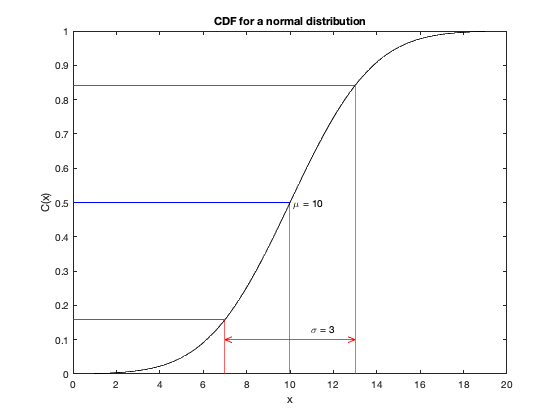

% no need to define x, mu or sigma here because they are defined above

% CDF for a normal distribution
C = 0.5*(1 + erf((x - mu)/(sigma*sqrt(2))));

% -----figure----- 
figure;
hold on;

% plot the CDF
plot(x,C,'k-');

% add blue lines for the mean and CDF at the mean and add text
g = gca;
plot([mu mu g.XLim(1)],[0 0.5 0.5],'b-');
text(mu+0.05*sigma,0.5,['\mu = ',num2str(mu)])
% add red lines for the standard deviation and CDF at those positions and
% add annotations
plot([g.XLim(1) mu-[sigma sigma]],[nearestpt(x,C,mu-sigma)*[1 1] 0],'r-');
plot([g.XLim(1) mu+[sigma sigma]],[nearestpt(x,C,mu+sigma)*[1 1] 0],'r-');
% arrow is a custom function, so it won't work in MATLAB
arrow([-sigma+mu sigma+mu],0.1*[1 1],'style','double','color','r');
text((2*mu+sigma)/2,0.13,['\sigma = ',num2str(sigma)],'HorizontalAlignment','center');

% add labels
% PN: the '' are used to enclose a character string (text in computer
% speak)
xlabel('x');
ylabel('C(x)');
title('CDF for a normal distribution');
set(gca,'Box','on');

The quantile function for a normal distribution is given by $Q(C) = \mu+\sigma\sqrt{2}\text{erf}^{-1}\, (2C - 1)$.

For a normal distribution, the skew and kurtosis are both 0.

### 1.3.2 Log-normal Distribution

While we live in a linear world, not all things behave in a linear way.  The log-normal distribution is common when values are limited to positive values and behave in an exponential way. Examples include species abundance, surface heat flow and trace element concentration.  I include trace element concentrations because they are frequently distributed in a way similar to log-normal distributions, although this assumption not technically correct because concentrations are constrained between 0 and 1,000,000 ppm whereas the log-normal distribution is unbounded to $+\infty$.

A log normal distribution is really a normal distribution in disguise as $\log(x)$ is normally distributed.  In linear space, the log-normal PDF is given by,

$P(x) = \exp (P_N(x)) = \frac{1}{x\sigma\sqrt{2\pi}}\exp\left(-\frac{(\log x - \mu)^2}{2\sigma^2}\right)$,

where $x \in (0,+\infty)$, i.e., $\mathbb{R}^+$, $\mu$ and $\sigma$ are the scale parameters, but *not* the mean and standard deviation, respectively.  *Note*: that I have used $\log$ for the natural logarithm instead of the commonly used $\ln$.  This choice is because MATLAB, like many computer languages, use have a built-in function log() for the natural logarithm.  If I use the base-10 logarithm, I will write $\text{Log}$ or $\log_{10}$, which in MATLAB is log10().

The PDF for a log-normal distribution is shown in the figure below.

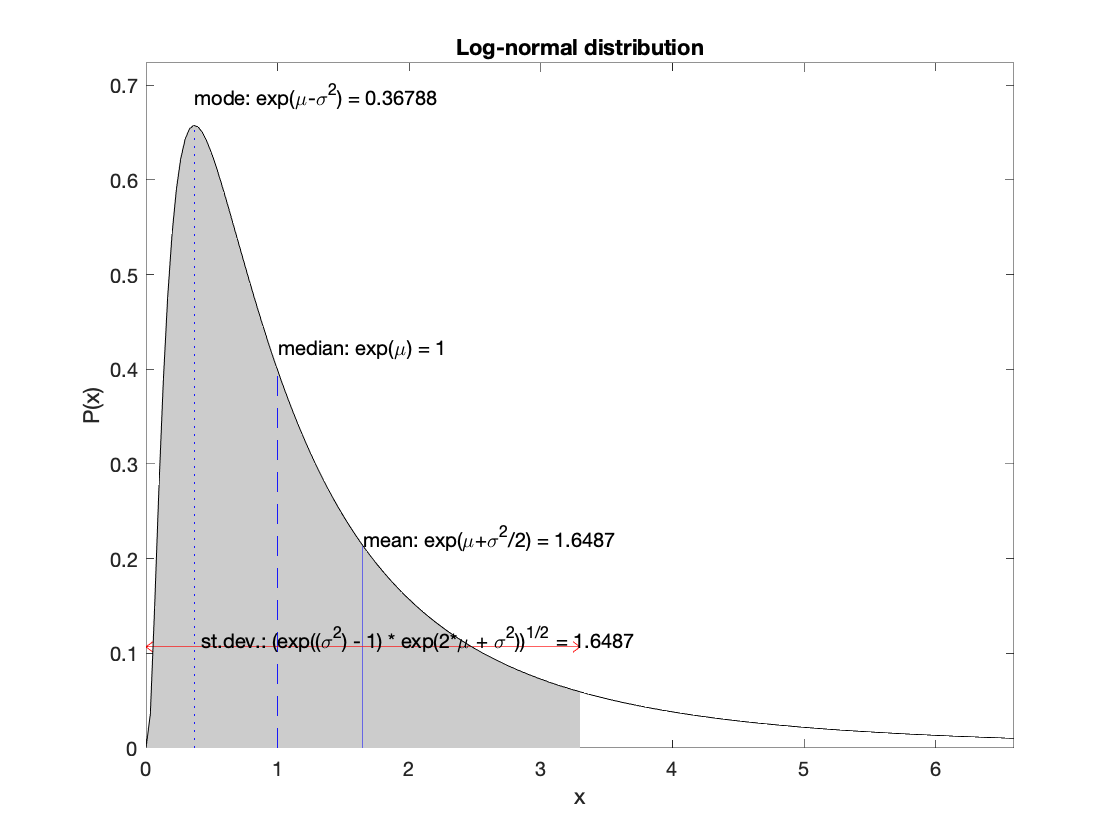

clear all;

% make a plot of a Gaussian with scale parameters mu and sigma
mu = 0;               % scale parameter
sigma = 1;              % scale parameter

mn = exp(mu + sigma^2/2);   % mean
md = exp(mu);               % median
mo = exp(mu - sigma^2);     % mode
s = sqrt(exp((sigma^2) - 1) * exp(2*mu + sigma^2)); % standard deviation

% creates a set of x values
x = [0:0.02*s:3*s+mn];    

% compute a log-normal curve
P = 1./(x*sigma*sqrt(2*pi)) .* exp(-(log(x) - mu).^2/(2*sigma^2));
P(1) = 0;

% -----figure----- 
figure;
hold on;

% annotations
% creates a vector to identify points between +/- sigma
ind = -s+mn <= x & x <= s+mn;
% plots a shaded region encompassing +/- sigma
h = fill([s+mn -s+mn x(ind) s+mn],[0 0 P(ind) 0],[0.8 0.8 0.8]);
% removes the line around the shaded region
set(h,'EdgeColor','none');

% plots a blue dashed line ('b--') for the location of the median
plot([md md],[0 nearestpt(x,P,md)],'b--');
text(md,1.05*nearestpt(x,P,md),['median: exp(\mu) = ',num2str(md)], ...
    'HorizontalAlignment','left');
% plots a blue solid line ('b-') for the location of the mean
plot([mn mn],[0 nearestpt(x,P,mn)],'b-');
text(mn,1.05*nearestpt(x,P,mn),['mean: exp(\mu+\sigma^2/2) = ',num2str(mn)], ...
    'HorizontalAlignment','left');
% plots a blue dotted line ('b:') for the location of the mode
plot([mo mo],[0 nearestpt(x,P,mo)],'b:');
text(mo,1.05*nearestpt(x,P,mo),['mode: exp(\mu-\sigma^2) = ',num2str(mo)], ...
    'HorizontalAlignment','left');

% add a red double arrow for standard deviation
arrow([-s+mn s+mn],0.5*nearestpt(x,P,mn)*[1 1],'style','double','color','r');
text(mo+0.05,0.55*nearestpt(x,P,mn), ...
    ['st.dev.: (exp((\sigma^2) - 1) * exp(2*\mu + \sigma^2))^{1/2} = ',num2str(s)], ...
    'HorizontalAlignment','left')

% plots the probability distribution
plot(x,P,'k-');

% add labels
xlabel('x');
ylabel('P(x)');
title('Log-normal distribution');
% get limits
ylim([0 1.1*max(P)]);
xlim([min(x) max(x)]);
% complete box around plot
set(gca,'Box','on');

The CDF for a log-normal distribution is given by


$$C(x) = \frac{1}{2} \left[1 + \text{erf}\,\left(\frac{\log(x) - \mu}{\sigma\sqrt{2}}\right)\right]$$


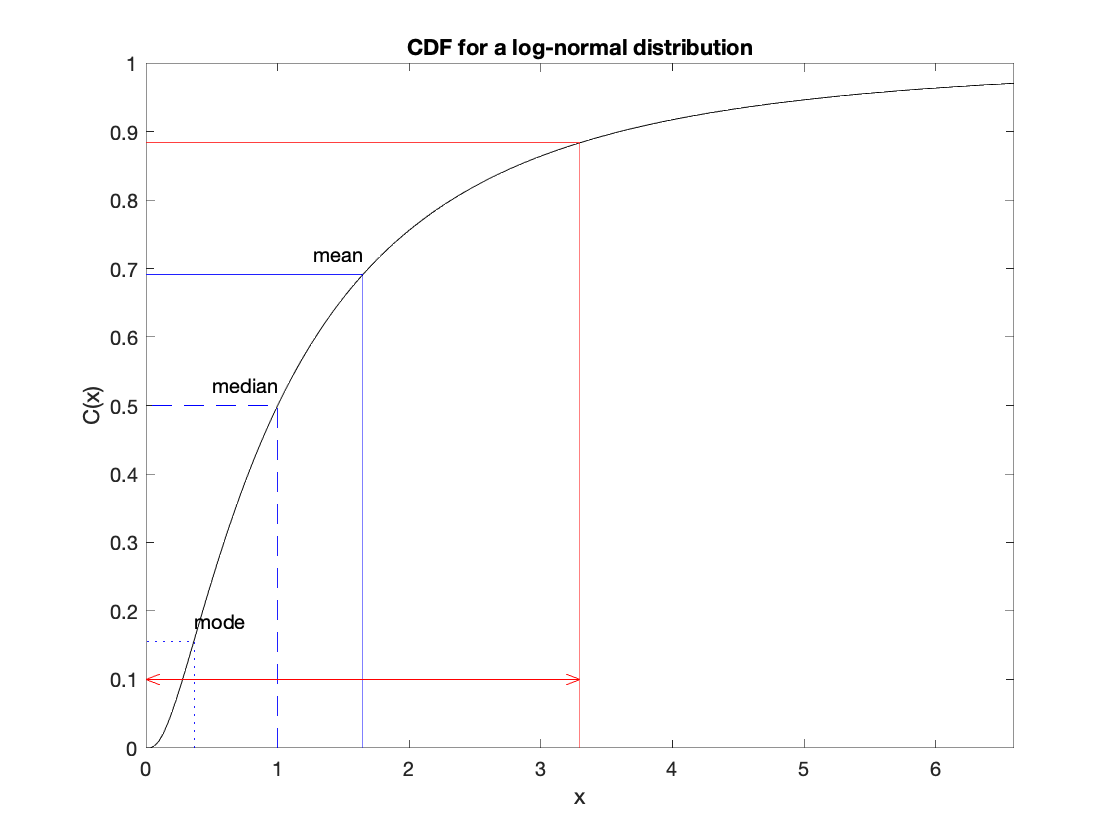

% CDF for a log-normal distribution
C = 0.5*(1 + erf((log(x) - mu)/(sigma*sqrt(2))));

% -----figure----- 
figure;
hold on;

% plot the CDF
plot(x,C,'k-');

% add blue lines for mean, median and mode.
g = gca;
plot([md md g.XLim(1)],[0 0.5 0.5],'b--');
text(md,0.53,'median','HorizontalAlignment','right');
plot([mn mn g.XLim(1)],[0 nearestpt(x,C,mn)*[1 1]],'b-');
text(mn,nearestpt(x,C,mn)+0.03,'mean','HorizontalAlignment','right');
plot([mo mo g.XLim(1)],[0 nearestpt(x,C,mo)*[1 1]],'b:');
text(mo,nearestpt(x,C,mo)+0.03,'mode','HorizontalAlignment','left');

% add red lines for standard deviation
plot([g.XLim(1) mn-[s s]],[nearestpt(x,C,mn-s)*[1 1] 0],'r-');
plot([g.XLim(1) mn+[s s]],[nearestpt(x,C,mn+s)*[1 1] 0],'r-');

% add red double arrow to show standard deviation range
arrow([-s+mn s+mn],[0.1 0.1],'style','double','color','r');

% add labels
xlabel('x');
ylabel('C(x)');
title('CDF for a log-normal distribution');
% fix x range
xlim([0 max(x)]);
% complete box around plot
set(gca,'Box','on');

The quantile function is given by $Q(C) = \exp(\mu + \sigma\sqrt{2}\text{erf}^{-1}\, (2C - 1))$.

### 1.3.3 Power-law Distribution

There are many small earthquakes and increasingly fewer as the energy released by earthquakes increase in a distribution that closely resembles a power-law distribution, which for earthquakes is termed the Gutenberg–Richter law.  Both grain and pore sizes can also often follow this type of distribution.  The distribution is given by

$N(x) = 10^{a - bx}$,

where $N$ is the occurrence frequency for a given value $x$, where $a$ and $b$ are scale factors.  The factor $a$ sets the zero intercept, while $b$ sets the rate at which the frequency falls decreases with increasing $x$.  While many phenomena result in power-law behaviour, they often violate the behaviour at low values of $x$, often rolling-off to a constant value.  It should also be noted that this is not strictly a PDF, though it could be normalized to become a PDF.

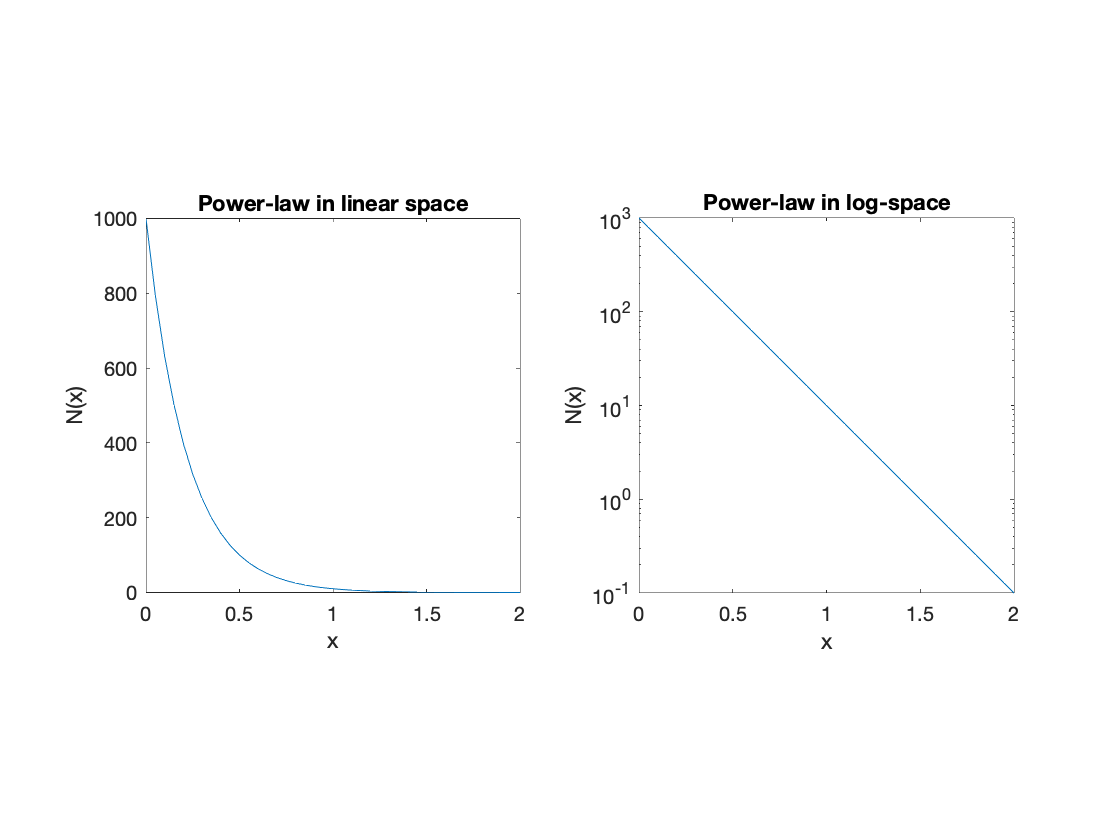

clear all;

% scale parameters for power law
% note there are multiple forms for power law distributions, but they are
% all relatively similar
a = 3;
b = 2;

x = [0:0.05:b];
N = 10.^(a - b*x);

% -----figure----- 
figure;
% power law in linear space
subplot(121);
hold on;
plot(x,N);
xlabel('x');
ylabel('N(x)')
set(gca,'Box','on');
axis square;
title('Power-law in linear space');

% power law in log-space
subplot(122);
semilogy(x,N);
xlabel('x');
ylabel('N(x)');
axis square;
set(gca,'Box','on');
title('Power-law in log-space')

### 1.3.4 Poisson Distribution

There are many processes that require counting: fission tracks, point counting, species, leaf serrations, floods, earthquakes, and volcanic eruptions.  All these processes are random, but have a low probability of observation and as a result follow what is known as a Poisson distribution,

$P(r) = \frac{\mu^{r} \exp(-\mu)}{r!}$,

where $\mu$ is the number of observed events and $P(r)$ is the probability that $r$ events are observed.  The events are generally linked to an interval in time, or space, and thus $r$ is the event rate, e.g., number of earthquakes over magnitude 8 per 100 years.  The probability function is only defined for zero and positive integer values, $\mathbb{N}_0$, of $r$, though $\mu$ may be any positive real number or zero, $\mathbb{R}_0^+$.  The $!$ indicates the factorial function, which is simply the product of all numbers between 1 and $n$, i.e., $n! = 1 \cdot 2 \cdot 3 \cdots (n - 1) \cdot n$, where $0! \equiv 1$.  For a Poisson distribution, $\mu = \sigma^2$.  For large $\mu$ the shape of the distribution approaches a normal distribution.

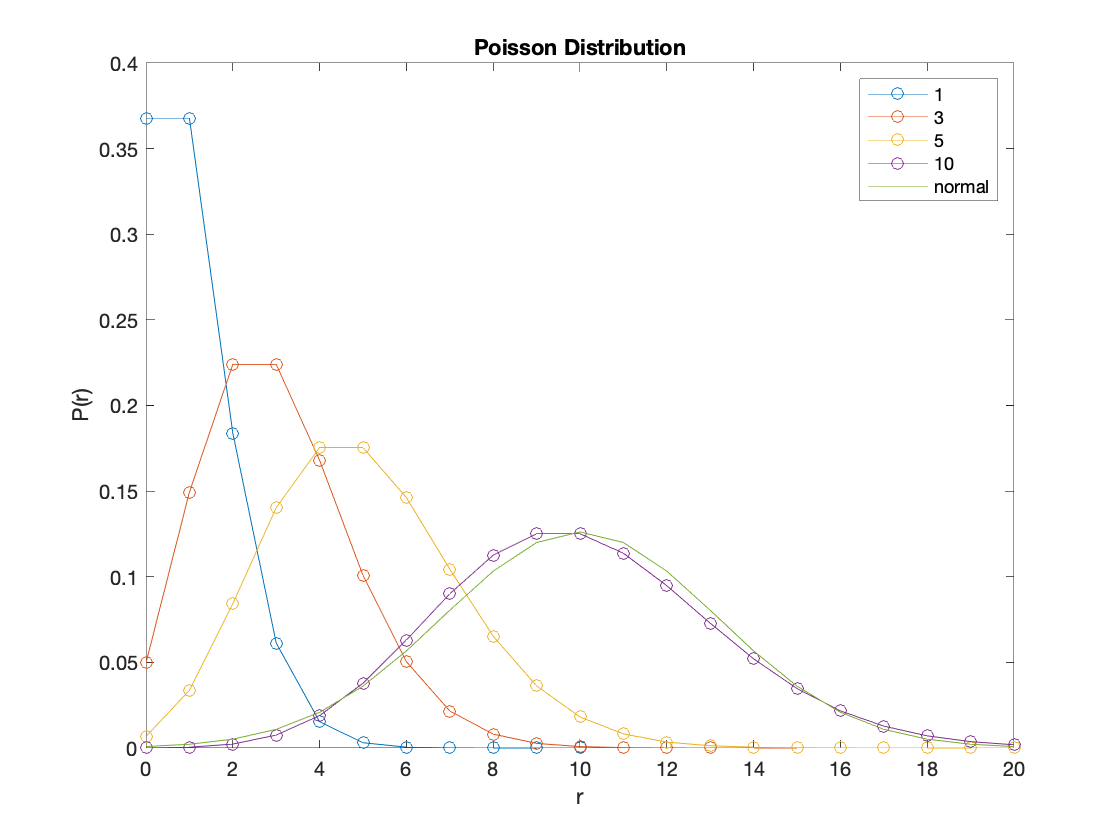

clear all;

% observations
mu = [1 3 5 10];

% occurrence
r = [0:20];
figure;
hold on;
for i = 1:length(mu)
    P = mu(i).^r*exp(-mu(i))./factorial(r);
    plot(r,P,'o-');
end
%gaussian
plot(r,gaussian(r,mu(end),sqrt(mu(end))),'-');
xlabel('r');
ylabel('P(r)');
title('Poisson Distribution');
for i = 1:length(mu)
    mu_str{i} = num2str(mu(i));
end
legend({mu_str{:},'normal'});
set(gca,'Box','on');

### 1.3.5 Circular and Spherical Statistics

In geoscience, many of our data are directional, meaning they are oriented in a hypothetical flat plane (declination), or have the additional dip as well (inclination).  Some processes can orient in a 360$^\circ$ such as the paleocurrent or wind direction and others are constrained to a 180$^\circ$ range such as geologic strike, geoelectric strike.  The phase tensor in magnetotellurics actually has a 90$^\circ$ ambiguity.  Magnetic data have both inclination and declination and therefore can point any direction relative to the center of a circle.  Mineral anisotropy is constrained to a hemisphere rather than a full sphere.  For the purposes of this course we'll make the assumption that any direction data we deal with are normally distributed.  We'll also need different types of plots for dealing with directional data: rose plots for 2-D data and stereonets for 3-D data.

Circular statistics can be also be used for periodic time data (daily, yearly) to examine cycle distributions.  To use time, you will need to convert the 

***Convention***** 1**: Computers (and math more generally) uses a $(0,2\pi)$ radian compass, but in geoscience we typically use a $(0,360)$ degree geographic compass or $(-180,180)$ signed geographic coordinates.  I have also formulated the codes to use degrees so you won't need to convert all your angles to radians, it shouldn't matter whether you use a $(0,360)$ or $(-180,180)$ convention because the codes will work either way.  It is a good idea to verify which conventions are used of any code/program you use.  To convert to radians, multiply your angle in degrees by $\pi/180$, and to convert to degrees, multiply the angle in radians by $180/\pi$.

***Convention***** 2**: Geoscience uses a clockwise from north convention whereas math uses a counterclockwise from east convention to define angles from 0.  The codes I have written account for this, but many generic rose and polar plotting functions in most languages will not.  In those cases, you need to convert from the geographic convention to the math convention.  To convert angles to get a function using math convention to put north at the top and increase clockwise,


$$\theta_m = 90^\circ - \theta_g$$


where $\theta_g$ is the geographic convention and $\theta_m$ is the math convention, both in radians.

#### 1.3.5.1 Circular means and standard deviations

First, we need to account for the number of angle repetitions per 360$^\circ$, $a$.  

To compute the mean, we need to convert the angles into Cartesian components:

$\displaystyle S = \sum_{i=1}^N \sin \left(a\theta\right)$ and $\displaystyle C = \sum_{i=1}^N \cos\left(a \theta \right)$

and then compute the mean (in degrees) from the inverse tangent


$$\mu_\theta = \frac{180}{a\pi} \tan^{-1}\left( \frac{S}{C} \right)$$


We need to be careful because the tangent function repeats every 180$^\circ$ ($\pi$ radians), i.e. S > 0 and C > 0 is in a different quadrant than S < 0 and C < 0 as angles with S > 0 and C < 0 are in a different quadrant than S < 0 and C > 0, despite the same sign on the ratios in both cases.  Many computer languages handle this problem by having two inverse tangent functions, one signed and one unsigned.  MATLAB has a function atan(S/C) which produces the unsigned inverse and atan2(S,C), where the former takes the ratio and the latter takes each component separately.

A resultant length for the directions can computed and used as an indication of the variance,


$$R = \frac{(S^2 + C^2)^{1/2}}{N}$$


with the standard deviation (in degrees) computed via


$$\sigma_\theta = \frac{180}{a \pi} (2(1 - R))^{-1/2}$$


The resultant length an advantages over the standard deviation: the result vector ranges from $[0,1]$, uniformly distributed angles to a single angle direction for all data whereas the standard deviation ranges from $[0,\infty)$.

#### 1.3.5.2 Circular probability distributions

A circular distribution that is normally distributed is called a wrapped normal distribution to statisticians.  They define the probability as 


$$P(\theta) = \frac{1}{\sigma\sqrt{2\pi}} \sum_{k = -\infty}^{\infty} \exp \left[-\frac{(\theta - \mu + 2\pi k)^2}{2\sigma^2} \right]$$


which allows for repeats every 360$^\circ$, hence the term $2\pi k$ in the exponential and the sum over all integer values of $k$ on $(-\infty,\infty)$.  That is a bit extreme for us since we only really record angles from $(-180,180)$ or $(0,360)$ and our repeat interval could be less than 360$^\circ$.  So let's reframe this equation for our uses in geoscience with repeats every $2\pi/a$ radians, and we really only need $k$ on $(-a, a)$ to account for the two angle range conventions.


$$P(\theta) = \frac{1}{\sigma\sqrt{2\pi}} \sum_{k = -a}^{a} \exp \left[-\frac{(a\theta - \mu + 2\pi k)^2}{2\sigma^2} \right]$$


For both of the above probability distributions, $\mu$, $\sigma$, and $\theta$ need to be in degrees (again, my MATLAB function handles those conversions for you).

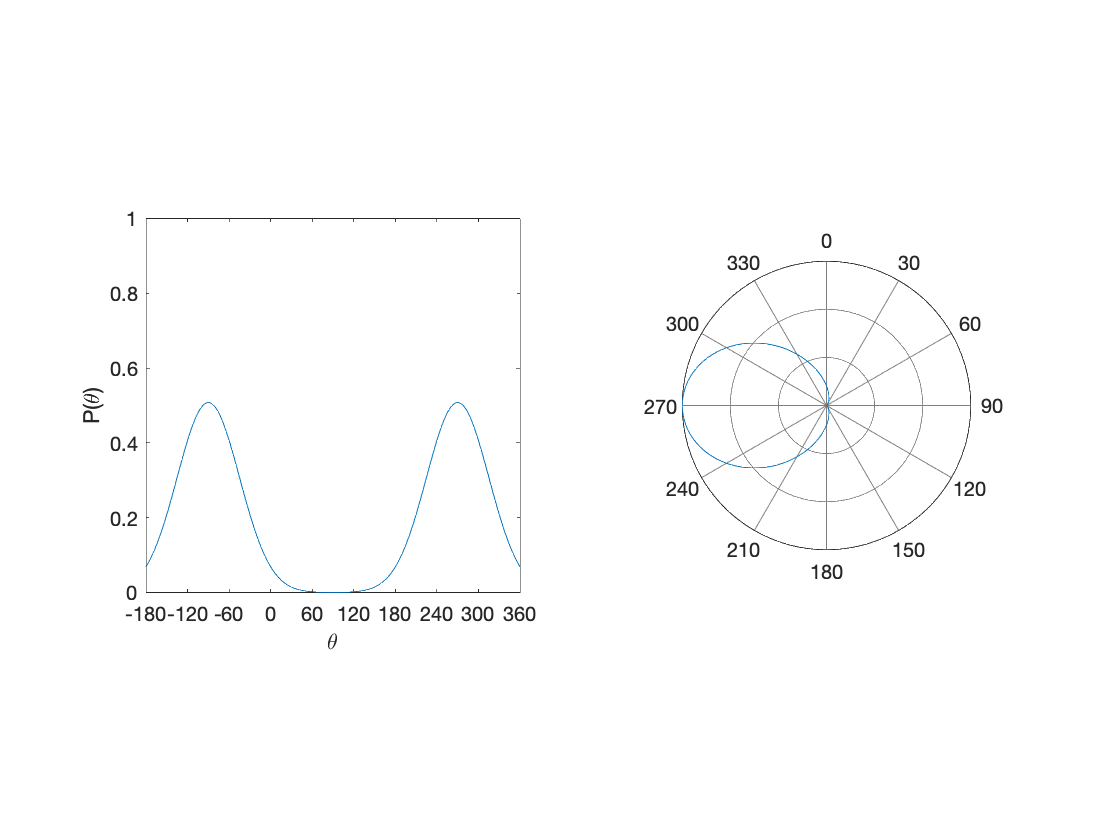

clear all;

mu = -90; % mean

sigma = 45; % standard deviation
a = 1; % number of repeats per 360 degrees

theta = [-180:2:360]; % angle in radians

k = [-1:1];
P = circnormal(theta,mu,sigma,a);
figure;
subplot(121);
hold on;
plot(theta,P);
set(gca,'XLim',[-180 360], ...
    'XTick',[-180:60:360]);
%xlim([-pi pi]);
xlabel('\theta');
ylabel('P(\theta)');
axis square;
set(gca,'Box','on');
ylim([0 1]);

subplot(122);
hold on;
%rosehist(thetas*pi/180,30);
%polar(-(theta*pi/180)+pi/2,P);
roseplot(theta,P);

# 2 Synthetic Data

## 2.1 Introduction

Before we deal too much with real data, I want to show you how to create synthetic data with various distributions.  There are two reasons for this: 1, we will use random distributions at times to demonstrate principles of data analysis, and 2, you may want to use simulated data to test your own processing schemes.  There are a number of methods to produce random numbers...turns out truly random is hard to create for a computer.  We won't get into these schemes as it is beyond the scope of this course and nearly all are good enough for most of our purposes.

## 2.2 Creating Random Data

### 2.2.1 Uniformly distributed random data

A uniform distribution is one in which the probability of observation is a constant, i.e., $P(x) = c$ where $c = (x_{\text{max}} - x_{\text{min}})^{-1}$.  In MATLAB, you can create a random sequence of numbers using the rand() function which will produce a set of random numbers on the interval (0,1).  To use it you need to supply rand() with the dimensions of a matrix you would like to produce.  If you only have one sequence of random numbers, then one of the dimensions will have the value 1.  So if I wanted to create a set of 5 random numbers in a row vector, I would call 

rand([1 5])

ans =     0.8119    0.1480    0.3269    0.0877    0.7446


If instead I wanted a column vector, I would call 

rand([5 1])

ans =     0.1176
    0.9652
    0.0726
    0.0847
    0.4673


Note that if I call it multiple times with the same argument, I will get different answers each time, which is good because it means that we can use the function to test how well a certain process behaves for randomly sampled data.

rand([1 5])

ans =     0.6991    0.5125    0.8329    0.6706    0.1878


rand([1 5])

ans =     0.3794    0.8472    0.6093    0.5905    0.3305


Let's try another example.  This time I am going to compute a number of random values, but I will do it a few times and plot a histogram with a common bin size so you can see how increasing the number of random values results in a more and more uniform result.

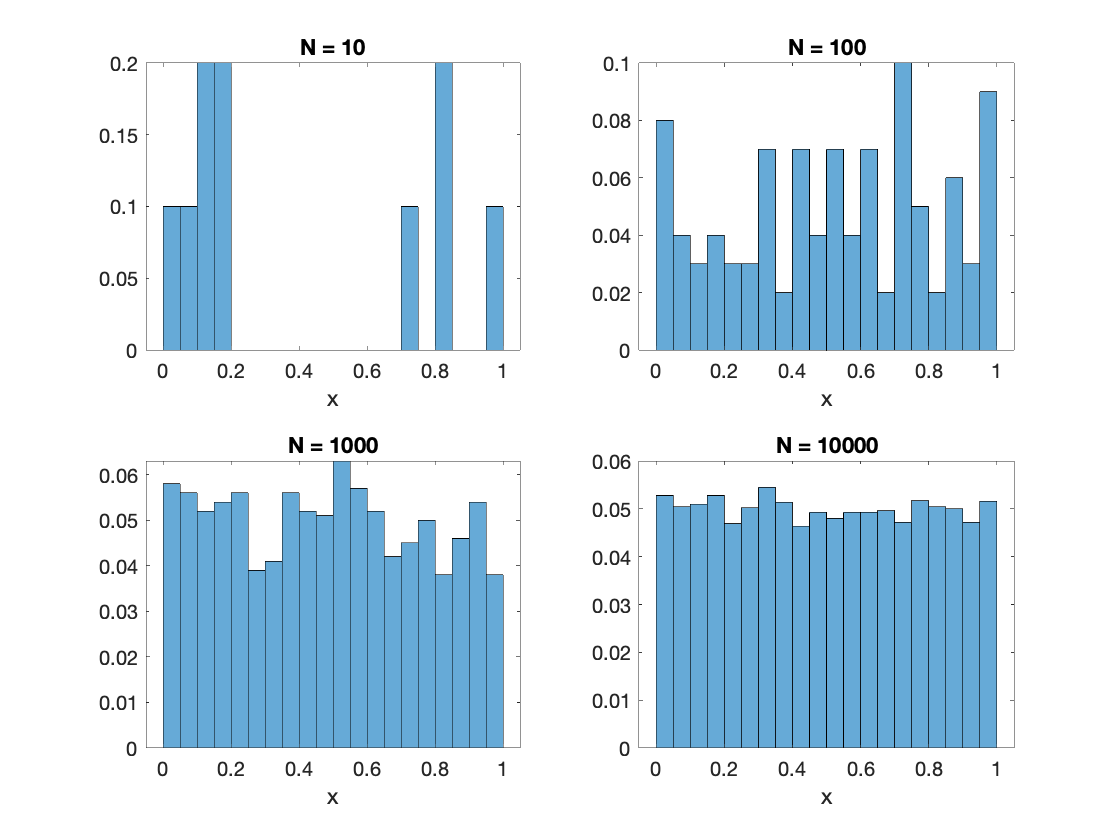

clear all;

% will create four separate sets of random numbers
N = [10, 100, 1000, 10000];

% -----figure----- 
figure;
for i = 1:length(N)  % for each value of N
    x = rand([N(i) 1]); % randomly generated set of numbers
    
    % create histogram
    subplot(2,2,i); % This is how to indicate the location of the subplot
    % PN: MATLAB refers to subplots with three numbers (row, column,
    % position), where position is read right to left, top to bottom.  If
    % the numbers are each less than 10, you can refer to them as 221, 222,
    % 223 and 224.
    
    histogram(x,'BinEdges',[0:0.05:1],'Normalization','probability');
    title(['N = ',num2str(N(i))]);
    xlabel('x')
end

In general we may want a different bounds for our random sampling than (0,1), rather we want our data to extend from $(x_{\text{min}},x_{\text{max}})$.   To do so, we will need to rescale the interval, which can be done pretty easily by linearly stretching, i.e., $x = x_{\text{min}} + (x_{\text{max}} - x_{\text{min}}) r$ where $r$ is the random number generated by rand().  Note the change in scale on the figure below.

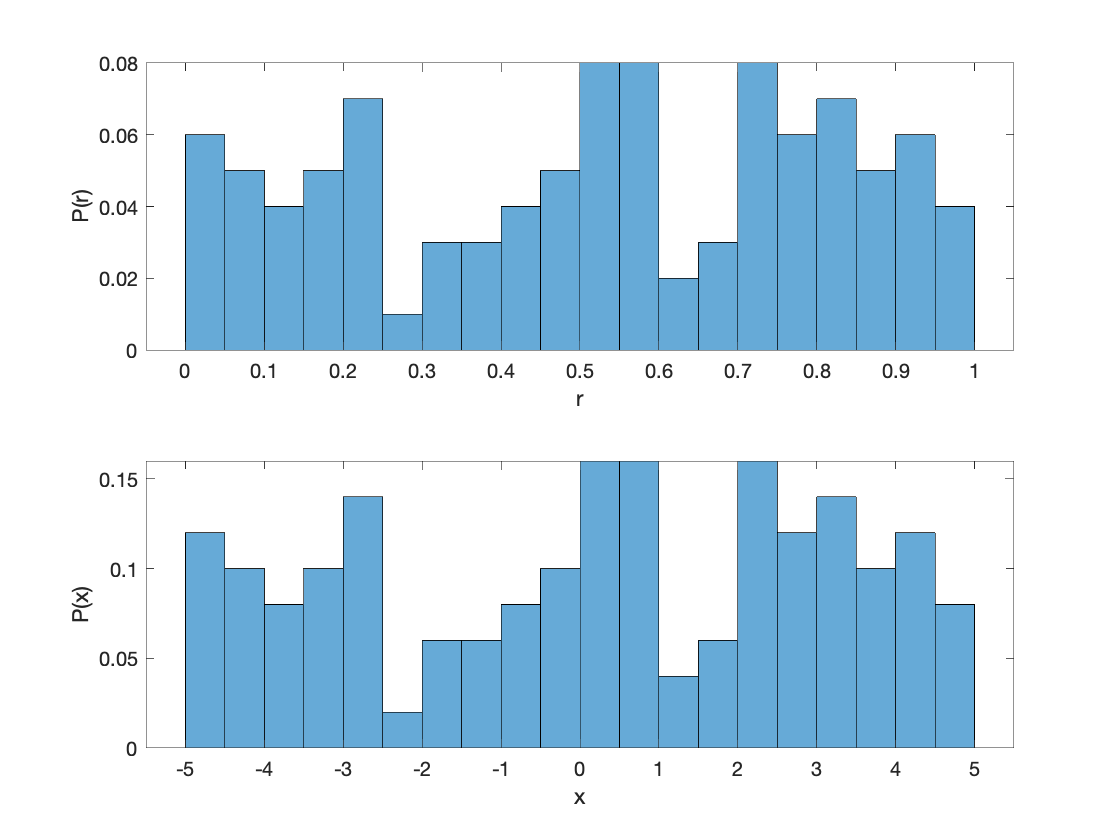

clear all;

% number of random points to create
N = 100;

% random distribution on (0,1)
r = rand([1 N]);

% range for rescaling
xmin = -5;
xmax = 5;

% rescale r to new range
x = xmin + (xmax - xmin)*r;

% -----figure----- 
figure;
subplot(211);
% histogram of r
histogram(r,'BinEdges',[0:0.05:1],'Normalization','probability');
% labels
xlabel('r');
ylabel('P(r)');

subplot(212);
% histogram of rescaled variable x
histogram(x,'BinEdges',[xmin:0.05*(xmax-xmin):xmax],'Normalization','pdf');
% labels
xlabel('x');
ylabel('P(x)');

### 2.2.2 Normally distributed random data

For normal distributions, we use a different MATLAB function to generate the random numbers, randn().  This function will create a normally distributed set of random numbers with a mean of 0 and a standard deviation of 1.  Note that mean and standard deviation may not be 0 and 1 from the random set, but as the number of samples increase, they will deviate smaller from the ideal less often (see values printed below the plot).

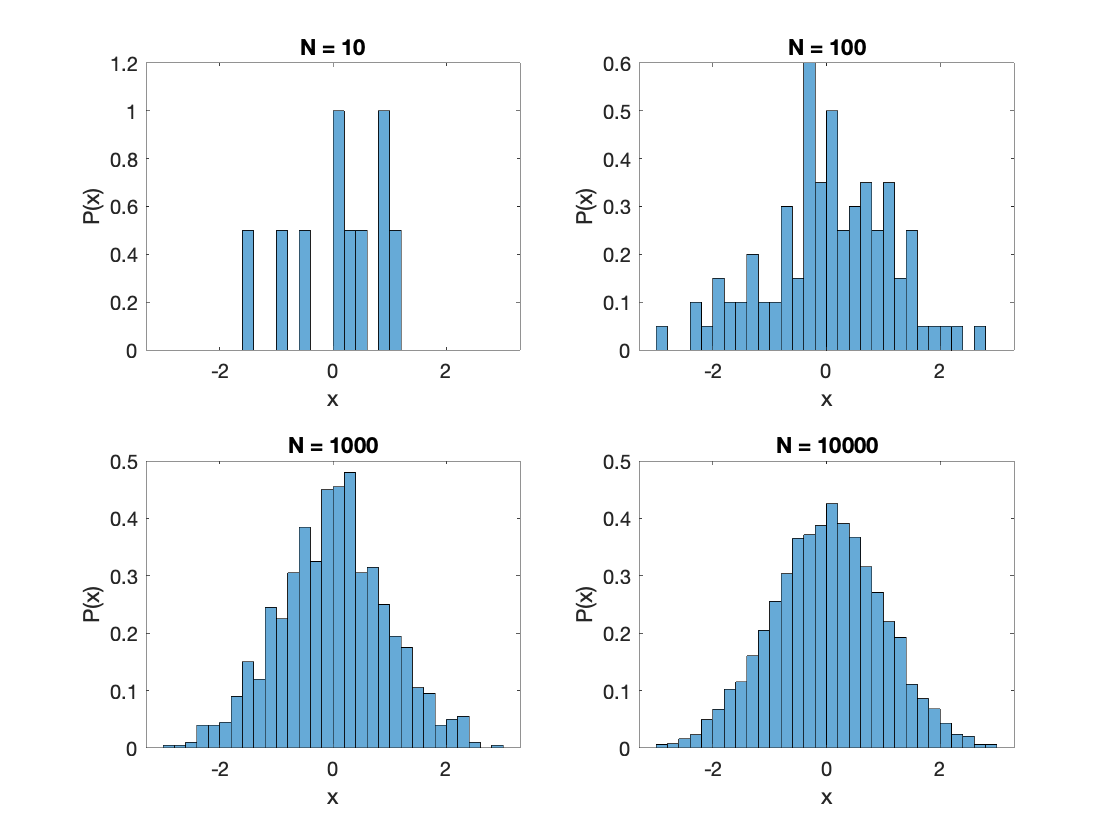

clear all;

% will create four separate sets of random numbers
N = [10, 100, 1000, 10000];

% -----figure----- 
figure;
for i = 1:length(N)  % for each value of N
    x = randn([N(i) 1]); % randomly generated set of numbers
    
    mu(i) = mean(x);
    sigma(i) = std(x);
    
    % create a subplot
    subplot(2,2,i);

    % create histogram
    histogram(x,'BinEdges',[-3:0.2:3],'Normalization','pdf');
    % labels
    title(['N = ',num2str(N(i))]);
    xlabel('x');
    ylabel('P(x)');
end


disp(['mu: ',num2str(mu)]);

mu: 0.11733    0.044117    0.012415     0.01016


disp(['sigma: ',num2str(sigma)]);

sigma: 0.8253       1.094     0.97839      0.9885


You may notice that for it takes a fair number of samples before the Gaussian shape becomes obvious.  So if your data don't look terribly Gaussian with a few samples, it doesn't necessarily imply that they are not well described by a normal distribution.  It may just imply that you don't have enough samples to accurately resolve the underlying distribution...and it's ok.

Again, we want to change our distribution from the standard one that MATLAB supplies to one that has the mean and standard deviation we desire.  To rescale the normal distribution produced by randn(), $r$, we need to stretch the width and recenter the mean, $x = \mu + \sigma r$.

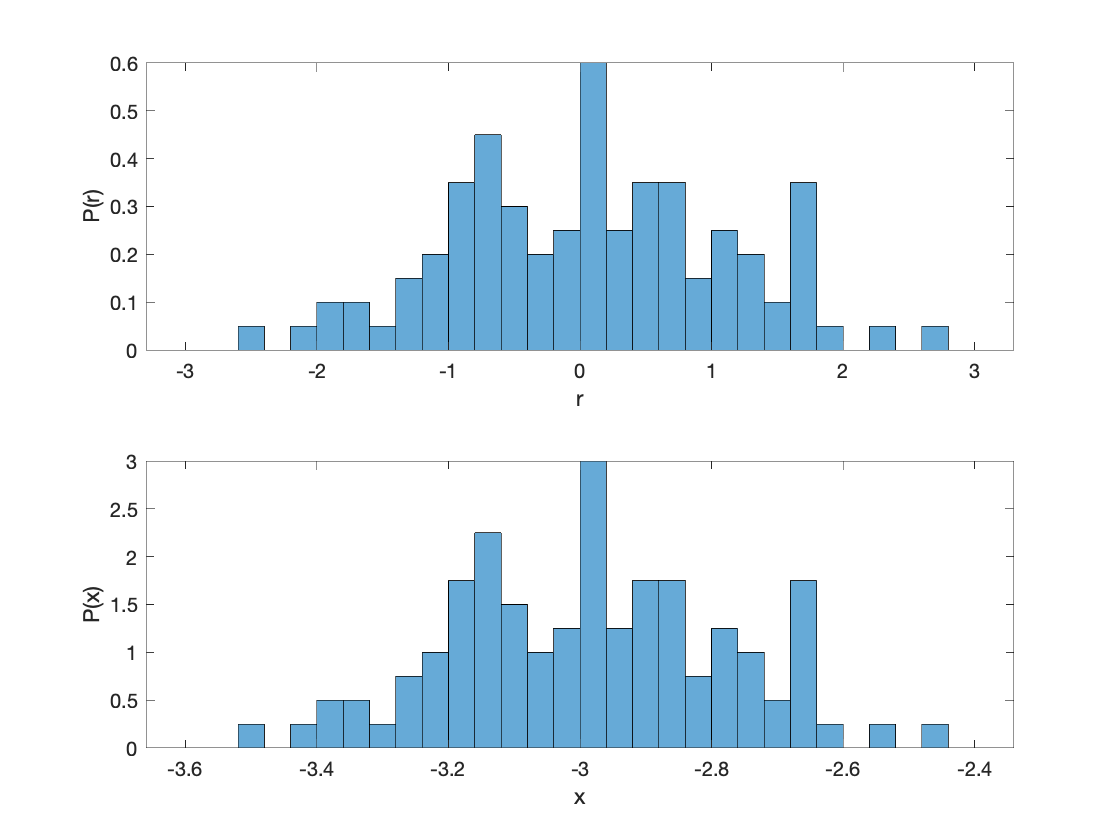

clear all;

% number of random samples
N = 100;

% random number
r = randn([1 N]);

mu = -3;
sigma = 0.2;

x = mu + sigma*r;

% -----figure----- 
figure;
subplot(211);
histogram(r,'BinEdges',[-3:0.2:3],'Normalization','pdf');
xlabel('r');
ylabel('P(r)');

subplot(212);
histogram(x,'BinEdges',[-3*sigma+mu:0.2*sigma:3*sigma+mu],'Normalization','pdf');
xlabel('x');
ylabel('P(x)');

### 2.2.3 Log-normally distributed random data 

There is no specific function in MATLAB to create a log-normal distribution, however, you can create a synthetic one by creating a normal distribution with the log-normal scale parameters first and then transforming the distribution, $x = exp(\mu + \sigma r)$ where $r$ is created by randn.

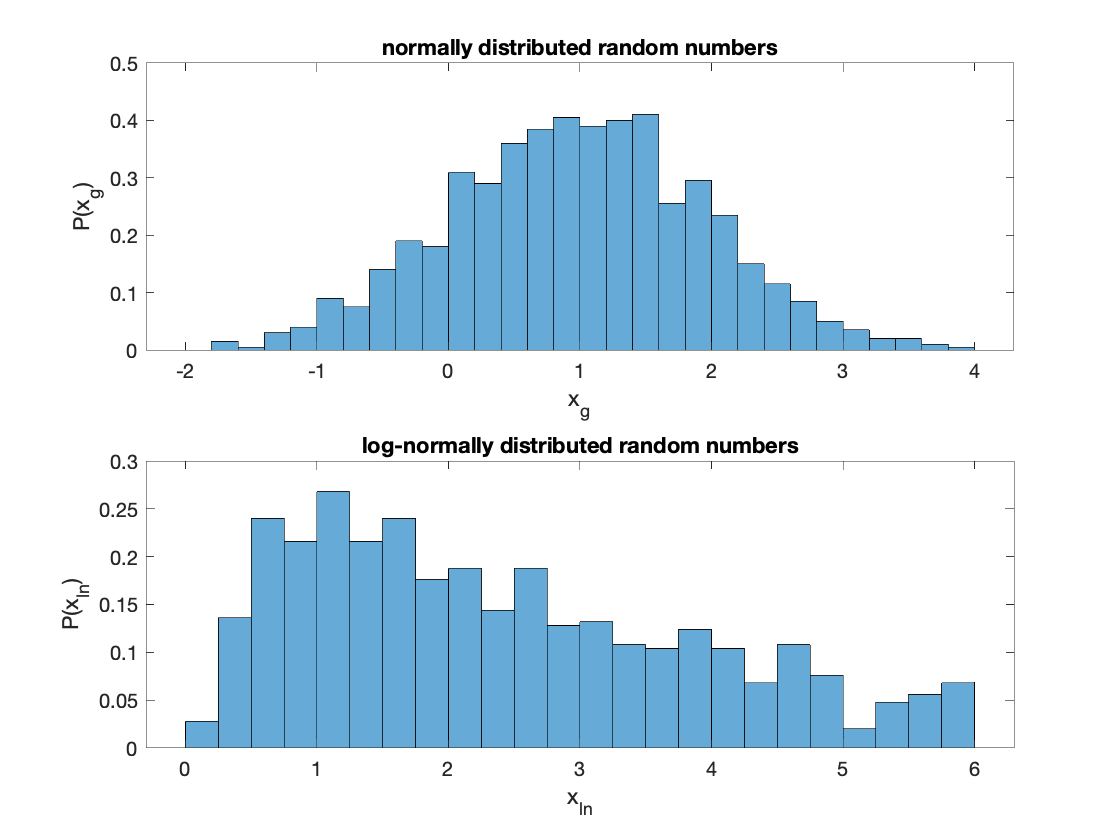

clear all;

% number of random samples
N = 1000;

% create normally distributed random numbers
r = randn([1 N]);

% scale factors for desired distribution
mu = 1;
sigma = 1;

% rescale normal distribution by scale parameters
xg = mu + sigma * r;

% transform to a log-normal distribution in linear space
xln = exp(xg);

% -----figure----- 
figure;
% normally distributed random numbers
subplot(211);
histogram(xg,'BinEdges',[-3*sigma+mu:0.2*sigma:3*sigma+mu],'Normalization','pdf');
% labels
xlabel('x_g');
ylabel('P(x_g)');
title('normally distributed random numbers')

subplot(212);
% log-normally distributed random numbers
histogram(xln,'BinEdges',[0:0.25:6],'Normalization','pdf');
% labels
xlabel('x_{ln}');
ylabel('P(x_{ln})');
title('log-normally distributed random numbers');

### 2.2.4 Poisson Distribution

Computing synthetic data with a Poisson distribution is a little more complicated than the other methods.  There are a number of algorithms for computing Poisson distributed random numbers.  The method used below is perhaps the easiest.

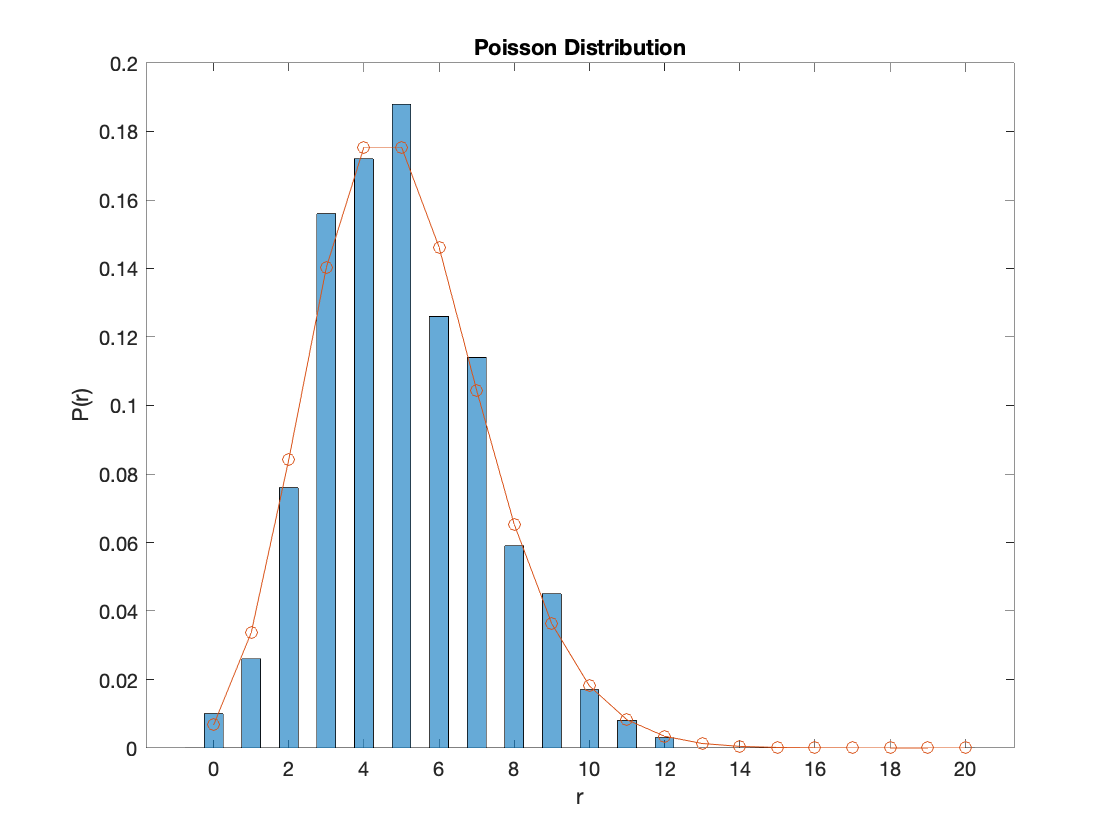

clear all;

% number of random numbers
N = 1000;

% mean
mu = 5;

L = exp(-mu);
% compute set of random numbers (x)
for i = 1:N;
    k = 0;
    p = 1;
    while p > L
        k = k + 1;
        
        u = rand([1 1]);
        p = p*u;
    end
    
    x(i) = k - 1;
end

r = [0:20];
Pp = mu.^r*exp(-mu)./factorial(r);

figure;
hold on;
histogram(x,'BinEdges',[-0.75:0.5:4*mu+0.25],'Normalization','probability');
plot(r,Pp,'o-');
xlabel('r');
ylabel('P(r)');
title('Poisson Distribution');
set(gca,'Box','on');

### 2.2.5 Empirical Distributions

Many of our distributions may be sufficiently Gaussian or log-normal that the scale factor calculations may still be reasonable.  However, not all sets of observations result in simple distributions that can be described by one of the common types.   When a distribution is suitably complex, we need another our scale factors may become effectively meaningless.  In these cases, we must resort to describing the distribution empirically or through visual representation.  But what do we do when we need to produce a random dataset that looks like our distribution?  We can use a technique called ***rejection sampling***.  Rejection sampling works by computing a uniform random number within the bounds of the sample values.  Then a second random number is computed between 0 and the maximum probability (or envelope) of the distribution.  If the value of the second random number is smaller than the probability at value of the first random number it is accepted, or it is otherwise rejected.  The process is continued until a value is until the desired number of samples are accepted.  I've included a function I wrote quite a while ago to do rejection sampling.  The function was originally used as part of a project that required simulating data using Monte Carlo analysis, which we will learn about shortly, to propagate uncertainties.

In the example below, I use rejection sampling to create a random distribution formed by the sum of three separate Gaussians with different scale factors.

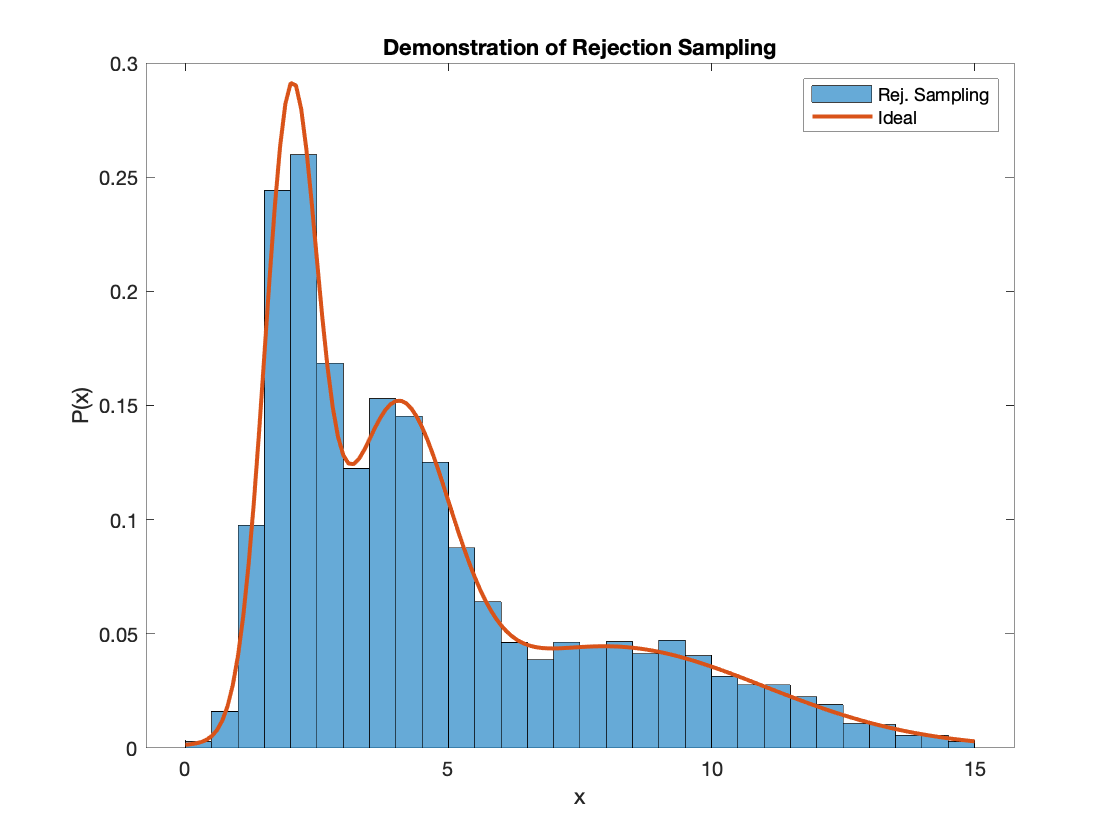

clear all;

% scale parameters for three normal distributions
mu = [2 4 8];
sigma = [0.5 1 3];

% create the combined distribution
dx = 0.1;
x = [0:dx:15];
% since we are creating a sum of three gaussians, start with a set of zero
% values for each x position.
P = zeros(size(x));
for i = 1:length(mu)
    % PN: I'm lazy and don't like to write the same equation every time I use
    % it so I wrote a gaussian function that will compute the gaussian
    % probabilities given a set of x values, the mean (mu) and standard
    % deviation (sigma).
    P = P + gaussian(x,mu(i),sigma(i));
end
% normalize probability so that it sums to 1
P = P/sum(P)/dx;

% number of random samples
N = 10^4;

% rejection sampling to produce random distribution
r = rejsample(x,P,N);

% -----figure----- 
figure;
hold on;
% histogram of random numbers
histogram(r,'BinEdges',[0:0.5:15],'Normalization','pdf')

% ideal gaussian
plot(x,P,'LineWidth',2);

% labels
legend('Rej. Sampling','Ideal');
xlabel('x');
ylabel('P(x)');
title('Demonstration of Rejection Sampling')
set(gca,'Box','on');

### 2.2.6 Circular Distributions

Like the previous example, creating a circular distribution requires creating a set of random numbers using rejection sampling.  The process is basically the same.

clear all;

mu = -30; % mean
sigma = 30; % standard deviation
a = 2; % number of repeats per 360 degrees

N = 100; % number of data

% create an ideal circular distribution
theta = [-180:2:180/a]; % angle in radians
P = circnormal(theta,mu,sigma,a);


% use rejection sampling to create a random sample set
thetas = rejsample(theta,P,N);

% compute statistics of
mus = circmean(thetas,a)

mus = -11.9600

[sigmas,R] = circstd(thetas,a);
sigmas = sigmas

sigmas = 16.3549

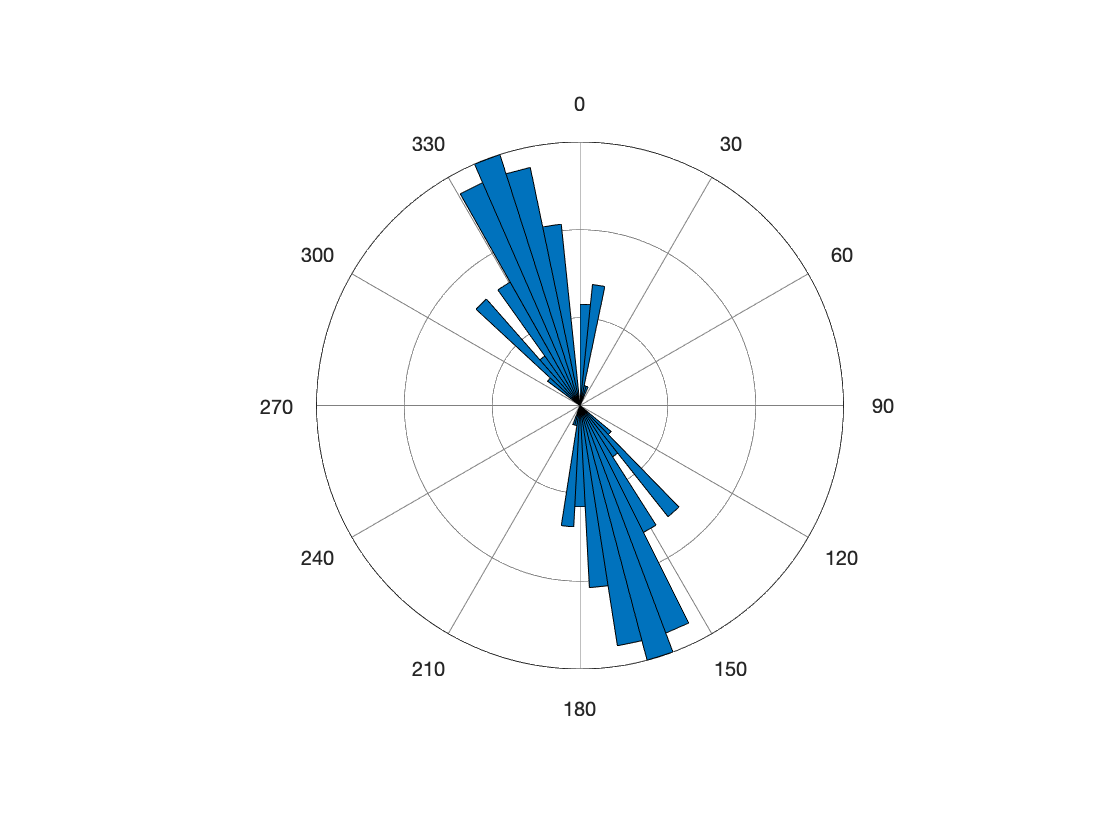


% plot distribution
figure;
hold on;
rosehist(thetas,30,a);

# 3 Propagation of errors

## 3.1 Introduction

Once you collect data one of the first things you will need to do is determine the uncertainties on your measurements.  Uncertainties may be provided by the laboratory running your analysis or they are reported by an instrument or given in an instrument manual.  Sometimes this is the only source of error in your observation, though not always.  Sometimes there are multiple sources of uncertainties from different steps in a process or preparation of a measurement that must be combined to somehow produce an overall uncertainty.  What if you average data, how do you combine the uncertainties (note: it isn't to average them)?  The same may be true if you are computing a quantity using a mathematical model.  How do you determine the uncertainty of the computed result?

There are two ways we can determine the uncertainties: 1. standard propagation of errors and 2. Monte Carlo analysis.  The first is preferred because it is faster and gives a rigorous result.  The second is performed when an analytic form does not exist, or it is not possible to determine because the problem is highly non-linear or hidden behind codes that you can't see under the hood.

## 3.2 Standard Propagation of Errors

Every mathematical formula has a different way to propagate errors to find the end result, but they all stem from one basic form.  Given a mathematical model, $y = f({\bf x})$, where ${\bf x} = {x_1, x_2, ... x_N}$,


$$\sigma_y = \left[ \sum_{i=1}^N \left(\frac{\partial f}{\partial x_i}\right)^2\sigma_{x_i}^2 \right]^{1/2}$$


where $\partial f/\partial x_i$ refers to the partial derivative of $f$ with respect to the model variable $x_i$.  So you will need a little calculus to figure out your uncertainty.

There is another model for errors that is more conservative (maximum error),


$$\sigma_y = \sum_{i=1}^N\left| \frac{\partial f}{\partial x_i}\sigma_{x_i}\right|$$


The second method may be better if you are uncertain about your errors or think that they are overly optimistic, but the first method is the statistically correct method as we will show in Section 3.3.

Let's explore a few common cases.

### 3.2.1 Arithmetic mean

When computing the mean of several samples, it is very important to understand how to estimate the uncertainty for an average of multiple values.  I will present the general case when the errors are all different and then ask you to derive the special case for when the errors are identical.  To propagate the errors, we need to identify the various components.  Suppose we collect a number of samples, $X = \{x_1, x_2, ..., x_N\}$, each has a distinct error, $\sigma_x = \{\sigma_{x_1}, \sigma_{x_2}, ..., \sigma_{x_i}\}$.  The average of the sample measurements is given by:


$$\bar{x} = f(x) = \frac{1}{N}\sum_{i = 1}^N x_i$$


with partial derivatives for each $x_i$,


$$\frac{\partial \bar{x}}{\partial x_i} = \frac{\partial f}{\partial x_i} = \frac{1}{N}$$


This derivative is about as simple as it gets.  The propagation of error equation is then


$$\sigma_{\bar{x}} = \left[ \frac{1}{N^2} \sum_{i=1}^N \sigma_{x_i}^2 \right]^{1/2}$$


**Exercise 1:** Show the uncertainty for an average is


$$\sigma_{\bar{x}} = \frac{\sigma_{x}}{\sqrt{N}}$$


when the uncertainties are equal for all samples, i.e., if $\sigma_{x_i} = \sigma_{x_j}$ for all $i \neq j$. In this case the uncertainty can be expressed as a constant $\sigma_{x_i} = \sigma_x$. * Note: This result is equivalent to the standard error.*

This relationship is particularly useful because you can use it to determine how many samples you should collect to achieve an uncertainty below a desired threshold.  Geophysicists call this method of reducing uncertainty stacking, which is used extensively to obtain more robust data by collecting multiple samples.  One of the beautiful things about stacking is that in many cases, if you collect a sufficient number of samples, you can actually resolve something that is otherwise obscured by noise.  Particle physicists take this to the extreme by collecting billions of collisions at colliders like CERN to things that are many orders of magnitude below the noise level.  It is also how astrophysicits are able to detect gravitational waves as part of the LIGO project, where the motions associated with the passing waves are also far below the noise level (Earth's hum).

### 3.2.2 Linear models

Consider a model for some process $y = mx + b$ where $m$ and $b$ are known from some physical model and $x$ is a measured quantity with an uncertainty $\sigma_x$.  The derivative of $y$ with respect to $x$ is $\frac{\partial y}{\partial x} = m$, which allows us to propagate the uncertainty,


$$\sigma_y = |m|\sigma_x$$


The $|m|$ comes from the $\sqrt{m^2}$.  In some cases our linear models have uncertainty on the slope, $\sigma_m$, and intercept, $\sigma_b$, that need to be incorporated into the calculation of uncertainty on $y$.  In these cases, we will need the additional partial derivatives,$\frac{\partial y}{\partial m} = x$ and $\frac{\partial y}{\partial b} = 1$.


$$\sigma_y = (m^2\sigma_x^2 + x^2\sigma_m^2 + \sigma_b^2)^{1/2}$$


### 3.2.3 Reciprocal models

A simple reciprocal model can be expressed as $y = mx^{-1}$, which has the derivative $\frac{\partial y}{\partial x} = -mx^{-2}$, and therefore propagates errors by


$$\sigma_y = \left( \frac{m^2}{x^4} \sigma_x^2 \right)^{1/2}$$


Again, if uncertainties in $m$ need to be incorporated,


$$\sigma_y = \left( \frac{m^2}{x^4} \sigma_x^2 + \frac{1}{x^2}\sigma_m^2\right)^{1/2}$$


### 3.2.4 Ratios

Ratios are basically a combination of the linear and reciprocal models, i.e., $y = x_1 x_2^{-1}$, which needs two partial derivatives, $\partial y/\partial x_1 = x_2^{-1}$ and $\partial y/\partial x_2 = -x_1 x_2^{-2}$.  To propagate the errors of a ratio,


$$\sigma_y = \left( \frac{1}{x_2^{2}} \sigma_{x_1}^2 + \frac{x_1^2}{x_2^4} \sigma_{x_2}^2 \right)^{1/2}$$


### 3.2.5 Exponential models

There are *a lot* of processes that are either exponential, $y = y_0\exp(bx)$, or exponential decay, $y = y_0\exp(-bx)$, so knowing how to propagate errors through these general formula is useful to know.  The derivative of an exponential function is given by $\partial y/\partial x = b y_0 \exp(b x)$ and for exponential decay, $\partial y/\partial x = -b y_0 \exp(-b x)$.  For exponential increasing functions, the error propagation is


$$\sigma_y = \sqrt{b^2 y_0^2} \exp(b x) \sigma_x$$


and for error propagation of exponential decay, the result is


$$\sigma_y = \sqrt{b^2 y_0^2}\exp(-bx) \sigma_x$$


## 3.3 Monte Carlo Analysis

Monte Carlo analysis is named for the casino in Monaco as it is random sampling-based approach to solving problems rather than an analytical framework.  It was originally used to solve complex particle physics problems in the early 1940's as part of the Manhattan Project (the building of the first atomic bomb).  Its advantage is that it can be used to determine the probability distribution that results processes that have many input variables with *a priori *constraints on the distributions of the inputs.  It is especially useful because the inputs may not be precisely known and/or the problems can exhibit remarkably complex mathematical behavior.  We will discuss some additional Monte Carlo applications later in the course, but for the moment I wish to demonstrate its usefulness for modeling error propagation.

Consider the exponential decay model above and it's propagation of uncertainty.  We will make conduct two tests: one using a simple normal distribution for the variable $x$ and show that the propagation of uncertainty is as expected and then a second case using an empirical distribution.

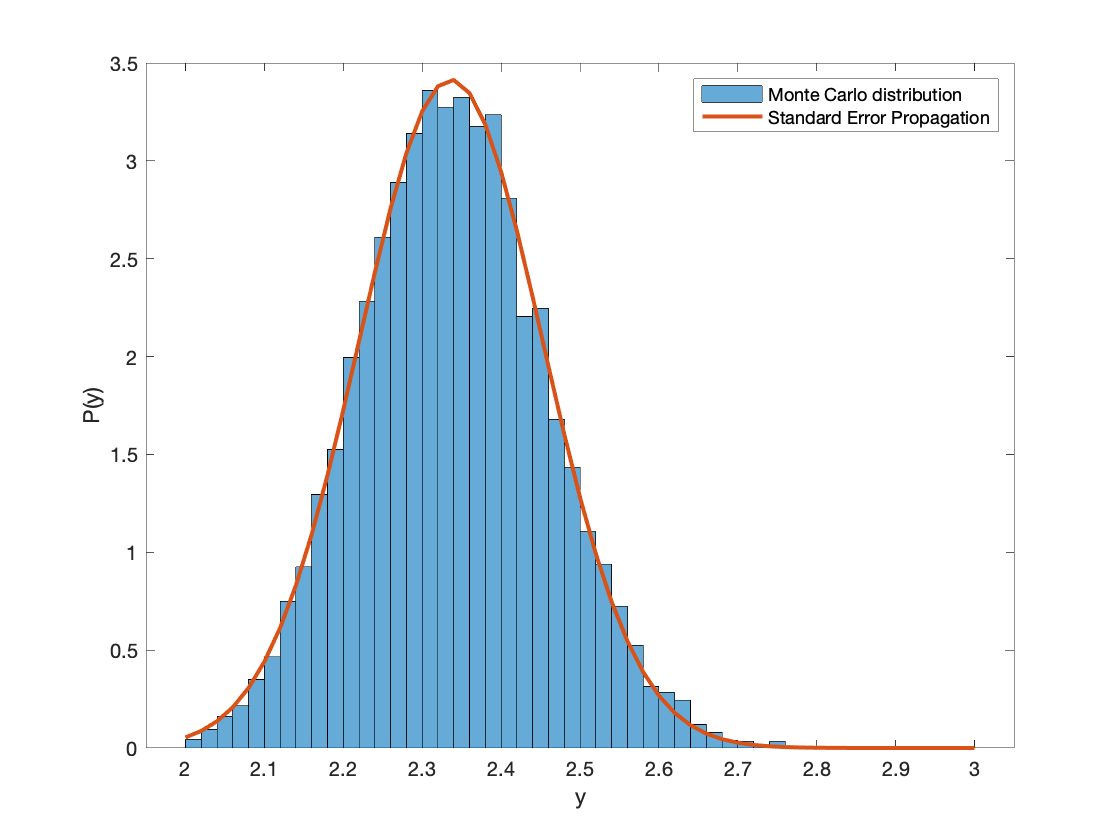

clear all;

% the x observation and uncertainty
x_mu = 0.5;
x_sigma = 0.1;

% the exponential model and mean y-value given a mean x-value
y0 = 3;
b = 0.5;
y_mu = y0*exp(-b*x_mu);

% standard propagation of errors to find sigma for y
y_sigma = sqrt((b*y0)^2)*exp(-b*x_mu)*x_sigma;

% Monte Carlo analysis
% --------------------
% number of realizations
N = 10^4;

% create a set of x values from a normal distribution with the observed
% mean and standard deviation
xp = x_mu + x_sigma*randn([N 1]);

% compute a distribution of y-values using the exponential model from the
% distribution of x-values
yp = y0*exp(-b*xp);

% -----figure----- 
figure;
hold on;
% plot Monte Carlo result
edges = [2:0.02:3];
histogram(yp,'BinEdges',edges,'Normalization','pdf');

% create and plot a Gaussian from the standard error propagation for y
Py = gaussian(edges,y_mu,y_sigma);
plot(edges,Py,'LineWidth',2);

legend('Monte Carlo distribution','Standard Error Propagation')
xlabel('y')
ylabel('P(y)');
set(gca,'Box','on');

Now, let's do the same analysis again, but this time, we will use a more complicated input distribution and rejection sampling (Section 2.2.4) to produce the input distribution.

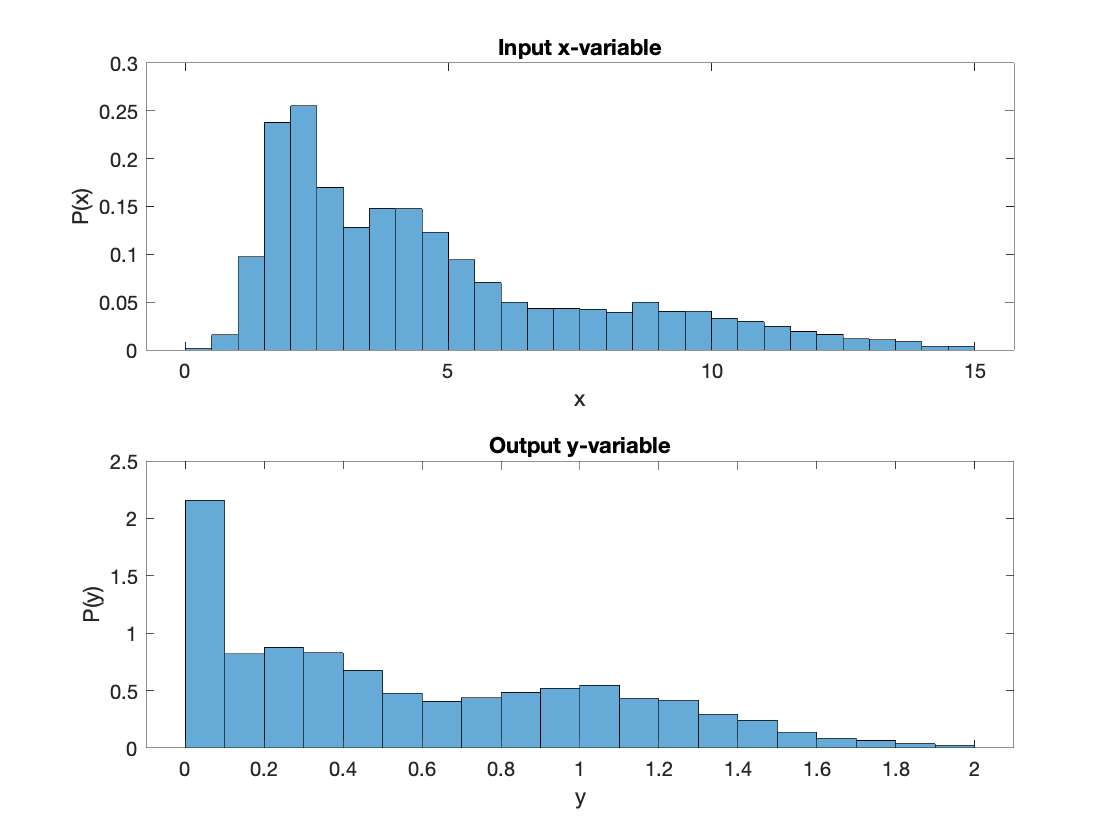

clear all;

% create the x distribution
mu = [2 4 8];
sigma = [0.5 1 3];

dx = 0.1;
x = [0:dx:15];
P = zeros(size(x));
for i = 1:length(mu)
    % I'm lazy and don't like to write the same equation every time I use
    % it so I wrote a gaussian function that will compute the gaussian
    % probabilities given a set of x values, the mean (mu) and standard
    % deviation (sigma).
    P = P + gaussian(x,mu(i),sigma(i));
end
P = P/sum(P)/dx;

% Monte Carlo analysis
% use rejection sampling to create the x distribution
N = 10^4;
xr = rejsample(x,P,N);

% exponential model parameters
y0 = 3;
b = 0.5;

% compute a distribution of y-values using the exponential model from the
% distributin of x-values
yp = y0*exp(-b*xr);

% -----figure----- 
figure;
% histogram of input x-values
subplot(211);
histogram(xr,'BinEdges',[0:0.5:15],'Normalization','pdf')

% labels
xlabel('x');
ylabel('P(x)');
title('Input x-variable')
set(gca,'Box','on');

% plot Monte Carlo result for y-values
subplot(212);
edges = [0:0.1:2];
histogram(yp,'BinEdges',edges,'Normalization','pdf');

% labels
xlabel('y')
ylabel('P(y)');
title('Output y-variable')

set(gca,'Box','on');

## 3.4 Central Limit Theorem

The central limit theorem states that if a number of IID random sample sets are added together, they will tend to a Gaussian distribution with finite mean and standard deviation even if the distributions themselves are not normally distributed.  Basically if you take enough samples the distribution of values will approach a Gaussian distribution.  Radiocarbon dates are a good example of this because radiocarbon dates often have very non-Gaussian shapes due to variable production of $^{14}$C though time as a result of changes in solar radiation.  However, if you collect enough radiocarbon dates, you should in most cases result in a good approximation for a Gaussian distribution radiocarbon dates.  In Section 4, we will see how this works.  We also often see a similar effect in modeling complex processes where non-Gaussian uncertainties in the input variables result in the Gaussian distribution of outputs.  However, it should be noted that this is not always true.

# 4. Sampling

## 4.1 Natural versus Observational Variability

When collecting samples, there are two types of variability, natural and observational.  ***Natural variability*** results from the natural environment and cannot be reduced by making more precise or additional measurements; though making additional measurements may reduce the uncertainty in the mean.  The sources of natural variability can sometimes be understood as a result of the processes and their spatial and temporal variability as well as the state (temperature, pressure, composition).  If the natural variability can be understood, it may be possible to select for samples that control or some of the factors that contribute the natural variability in a systematic way thereby reducing the variability.  For example, the annealing temperature of apatite is affected by fluorine concentration.  Another example is the trace element concentrations in arc volcanics which weakly correlate with crustal thickness.

***Observational variability*** results from uncertainties that arise in measurement.  Observational variability can be reduced by making more accurate and precise measurements or by making replicate measurements; though the former is not always viable.  Observational uncertainty is often smaller than natural variability and can therefore be ignored in some analyses of the data, when natural variability is large.

When results are presented, the observational uncertainty is presented, but typically not the natural variability.  Some studies trying to characterize the natural variability of a site, while others may only collect one or two samples from a site and therefore may not capture the natural variability.  Neither is inherently correct or incorrect as it depends upon the question under study, but in the case of the latter, one must be aware that the reported uncertainties may not be an accurate estimate of the true mean.

## 4.2 Sample size

When observational uncertainty is small, the uncertainty in the mean of a small sample set is governed by the natural variability.  However, with a large sample set, the uncertainties in the mean become small whereas the natural variability may still be large.  So how many samples do you need to collect to reliably observe a process?  We have already discussed how many samples you will need to collect to reduce observational variability in the Section 3.2.1.  

In the example below, we will be looking at natural variability and place an observational uncertainty on our synthetic data.  The test is based on synthetic data generated with a normal distribution.  In this default case, the true mean of the observations is 0, the natural uncertainty is set to 1, and the measurement uncertainty is set to 0.05.  We simulate collecting a sample set for analysis, anywhere from 1 to $10^4$ samples.  We then simulate collecting the data over and over again ($10^4$ times) to see the range of possible results had we only run the experiment once.

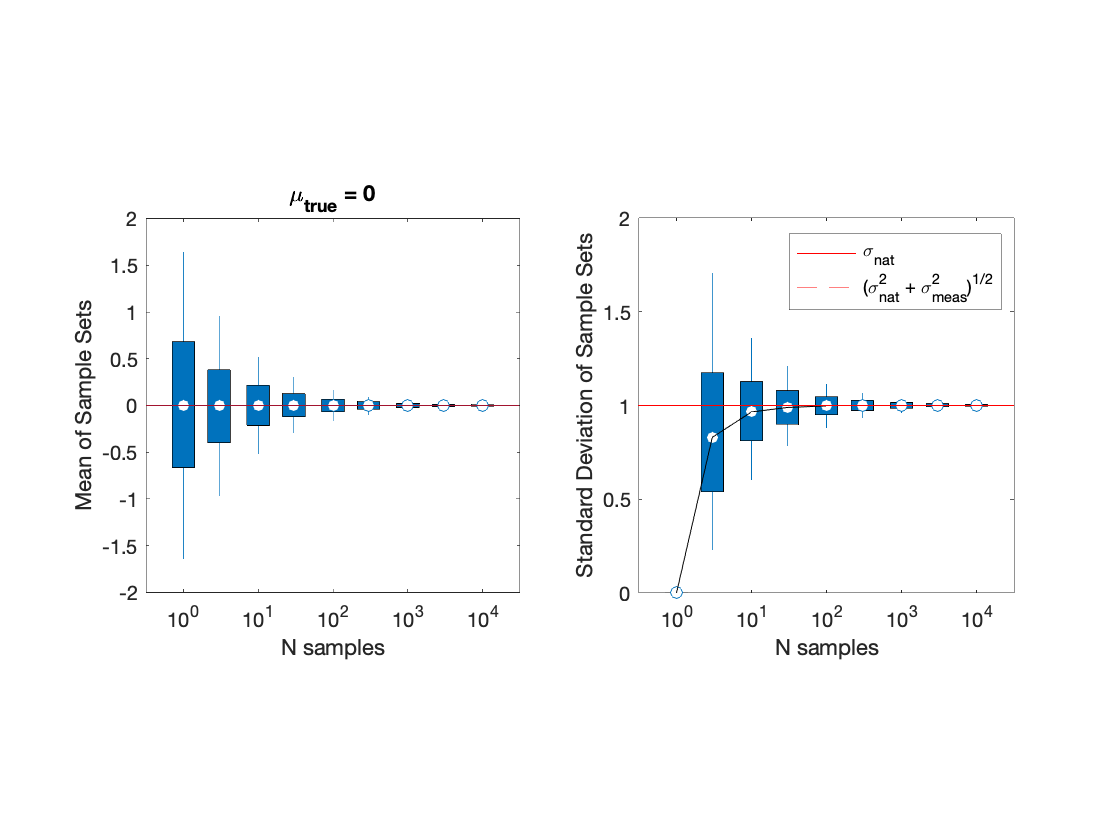

clear all;

% true mean
mu_true = 0;

% natural variability
sigma_nat = 1;
% measurement variability
sigma_meas = 0.05;

% Number of trials
nt = 10^4;
% Number of samples in each set
ns = [1 3 10 30 100 300 1000 3000 10000];

% true distribution
xg = [-3*sigma_nat+mu_true : 0.02*sigma_nat : 3*sigma_nat+mu_true];
Pg = gaussian(xg,mu_true,sigma_nat);

% now create nt sample sets of size ns and compute the scale parameters to
% store for analysis
for i = 1:length(ns)
    % create normally distributed random variables
    xs = mu_true + sigma_nat*randn([ns(i) nt]) + sigma_meas*randn([ns(i) nt]);
    
    mu{i} = mean(xs,1);
    sigma{i} = std(xs,0,1);
    ms(i) = median(sigma{i});
end
clear xs;

% -----figure-----
figure;
% Mean of Sample Sets
subplot(121);
% Make a box and whisker plot (on a log10 scale)
whisker(0.3,log10(ns),mu);
% PN: MATLAB doesn't have a great box and whisker plot, so I wrote my own.
hold on;
% plot true mean
xl = [-0.5 log10(ns(end))+0.5];
plot(xl,[mu_true mu_true],'-');

% x-scale annotations for a log10 scale
for i = 0:round(log10(ns(end)))+1
    xtic(i+1) = i;
    xticlbl{i+1} = ['10^{',num2str(i),'}'];
end
set(gca,'Box','on','XLim',xl,'XTick',xtic,'XTickLabel',xticlbl)

% labels
title(['\mu_{true} = ',num2str(mu_true)]);
xlabel('N samples');
ylabel('Mean of Sample Sets');
axis square;

% Standard Deviation of Sample Sets
subplot(122);
whisker(0.3,log10(ns),sigma);
hold on;
plot(log10(ns),ms,'k-');
% natural variability
p(1) = plot(xl,[sigma_nat sigma_nat],'r-');
% combined variability (propagation of errors
p(2) = plot(xl,sqrt(sigma_nat^2+sigma_meas^2)*[1 1],'r--');
legend(p,'\sigma_{nat}','(\sigma_{nat}^2 + \sigma_{meas}^2)^{1/2}')
% x-scale annotations
set(gca,'Box','on','XLim',xl,'XTick',xtic,'XTickLabel',xticlbl)
% labels
xlabel('N samples');
ylabel('Standard Deviation of Sample Sets');
axis square;

This result is very interesting, and somewhat expected and somewhat surprising.  If you run the experiment 1 time, then you have a large range in values that can deviate significantly from the true result (no surprise there).  As we increase the number of samples in our sample set, the limit approaches the true mean.  If we take a large number of samples the variability in our sample set is basically equivalent to the error propagation of the natural and measured variability.  Here comes the surprise.  When we collect a few samples, we could estimate an uncertainty greater or less than the error propagation result, but the uncertainty we calculate is likely to be biased towards a low uncertainty estimate.  I'll say that one more time, we are likely to underestimate the true uncertainty when we take a limited number of samples.  By 10 samples we are doing pretty well and by 30 we basically are centered about the true variability (just as likely to over- as under-estimate the uncertainty).  However, depending on how accurately we want to characterize the natural variability, we may need upwards of 300 samples.

I will stress that there is a practical side to sampling that is not captured by statistics (it is called money and/or time).  Collecting samples takes both time and money and one or both are often in short supply.  As a result, we often have to live with statistically suboptimal sampling.  Just be aware that it means you are likely underestimate the variability of a system.

The example above was run for a case where the natural variability $\gg$ measurement uncertainty.  What if they are equal?  What if measurement uncertainties $>$ natural variability?

## 4.3 Histograms

You have already seen histograms, all of the blue bar charts above.  A histogram is chart that gathers a given sample set, $X = \{x_1, x_2, ... x_N\}$ into discrete bins based on value.  Given a set of $m+1$ values for the bin edges, $\Xi = {\xi_1, \xi_2, ..., \xi_m,\xi_{m+1}}$, the number of data in the $j$-th bin is


$$n_j = \sum_{i = 1}^{N} \begin{cases}1,& \text{if } \xi_{j} \leq x_j < \xi_{j+1} \\ 0, &\text{otherwise}\end{cases}$$


where $N$ is the number of data in $X$.  Basically this just says that the number of data in each bin is the number of data that fall within the bounds of the edge values of said bin.

There are a few sticky particulars, how many bins do you use?  How many bins should you use?  Should the data be normalized and if so, how?

### 4.3.1 Bin width

There are some generally accepted rules for the number of bins, but no one seems to agree on what that number should be.  However, these rules can be easily violated if the presentation of your data permit it.  For example suppose you have histograms for a few sample sets.  You may want to use the same bin edges for a histogram associated with each sample set.  A distribution can be bimodal, but you might find that the standard bin widths hide the bimodality that very well could be a real signal.  That said, here are a few of the number of bin rules.

*Square-root rule*:


$$m = \sqrt{N}$$


*Sturges' rule*:


$$m = 1 + \log_2 N$$


*Scott's rule*:


$$w = \frac{3.5 s}{\sqrt[3]{N}}$$


where $w$ is the width of the bin rather than a specific number of bins.

*Freedman–Draconis rule*:

This bin width method is better for skewed or heavy-tailed distributions and is typically less sensitive to outliers than the other methods.  The bin width is estimated by


$$w = \frac{2\: \text{IQR}(X)}{N^{1/3}}$$


where IQR is the interquartile range (difference between the 0.75 and 0.25 quantile values).

Personally, I try to balance the number of bins (fewest necessary) with the number needed to reasonably characterize systematic variations in the distribution.  I often plot $\bar{x}$ and $\bar{x} \pm s$ as well so that the statistics are directly shown on the plot relative to the peak(s) of the histogram.

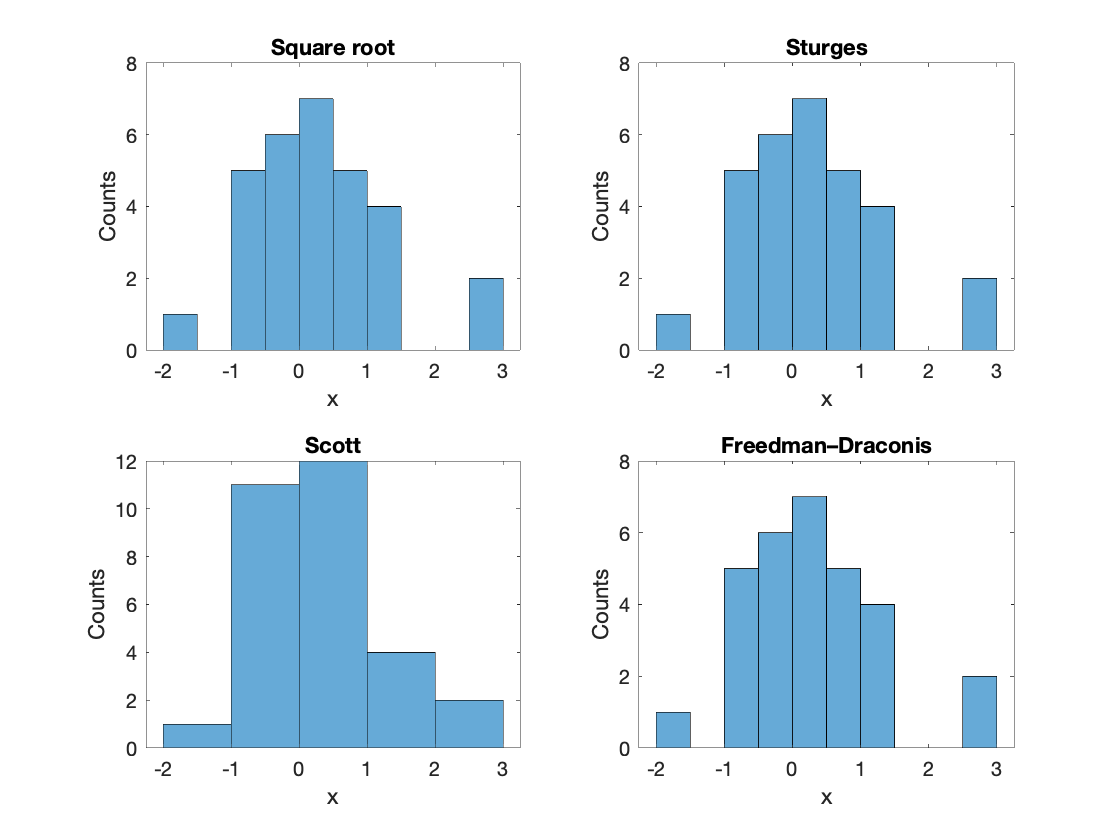

clear all;

% create a normally-distributed random dataset
N = 30;
x = [randn([N 1])];

% -----figure-----
figure;
subplot(221);
histogram(x,'BinMethod','sqrt');
xlabel('x');
ylabel('Counts');
title('Square root');

subplot(222);
histogram(x,'BinMethod','sturges');
xlabel('x');
ylabel('Counts');
title('Sturges');

subplot(223);
histogram(x,'BinMethod','scott');
xlabel('x');
ylabel('Counts');
title('Scott');

subplot(224);
histogram(x,'BinMethod','fd');
xlabel('x');
ylabel('Counts');
title('Freedman–Draconis');

### 4.3.2 Normalization

The normalization of a histogram will not change the shape, but it will change the values on the vertical axis.  An unnormalized histogram simply plots the height of each histogram relative to the number of data (or counts) in each bin.  The normalization that you choose depends on what you want to show.  If you want to plot an idealized PDF on the histogram, then use the PDF normalization.

*Count density*:

The count density is the number of data within each bin divided by the width, $h_i = n_i/w$.

*Probability*:

The height of bars are normalized by the total number of data, $h_i = n_i/N$.

*PDF*:

The bar heights represent the probability density in each bin, $h_i = n_i/(Nw)$.

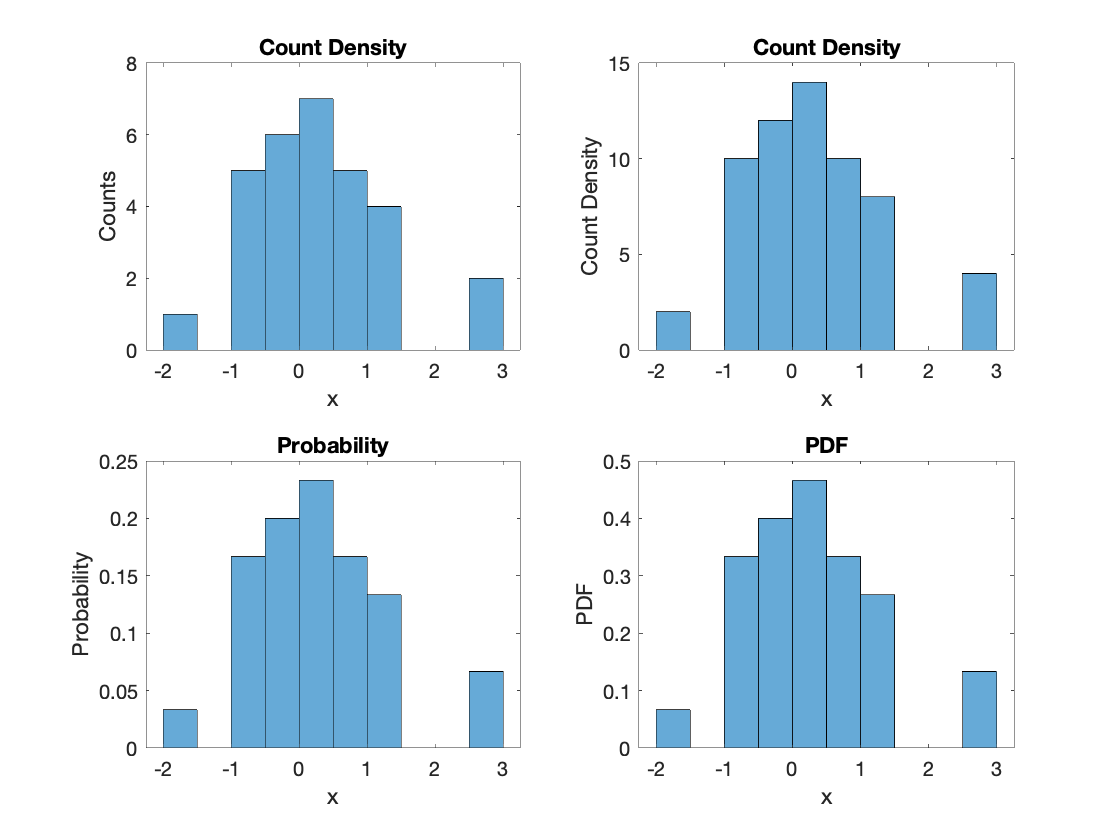

% don't clear, use same synthetic data as above

% -----figure-----
figure;
subplot(221);
histogram(x,'BinMethod','sqrt','Normalization','count');
xlabel('x');
ylabel('Counts');
title('Count Density');

subplot(222);
histogram(x,'BinMethod','sqrt','Normalization','countdensity');
xlabel('x');
ylabel('Count Density');
title('Count Density');

subplot(223);
histogram(x,'BinMethod','sqrt','Normalization','probability');
xlabel('x');
ylabel('Probability');
title('Probability');

subplot(224);
histogram(x,'BinMethod','sqrt','Normalization','pdf');
xlabel('x');
ylabel('PDF');
title('PDF');

## 4.4 Empirical Density Estimation

Many of the histograms shown above are spiky due to their discrete nature and depending upon how well-sampled the distribution is, may have gaps between the columns.  However, the data we collect often are continuous up to the precision of our measurements and if it were possible to measure the entire population, generally smoother than the histograms we generate from a few data.  But there is a way to produce smooth histograms from discrete data known as density estimation.  Below, I focus on two different types of density estimation: probability density estimation (PDE) and kernel density estimation (KDE). Both methods are somewhat similar but there is a key difference related to how data uncertainties are used.  With PDE, a distribution is produced at each observation its associated uncertainty.  The set of individual distributions is then summed and normalized to produce a single smoothed density estimate.  In KDE, the contribution of each observation to the smooth distibution is done via a kernel function not dissimilar to PDE except a bandwidth is used to scale the kernel.  Data uncertainties can be incorporated by scaling the bandwidth for each observation and/or as weights on the contribution of a kernel to the summed and normalized distribution.

How to choose between PDE and KDE?  PDE seems like the more intuitive choice at first glance because it involves using the uncertainty in the data to directly produce the smooth density estimate whereas KDE seems to replace this uncertainty with a user defined, somewhat arbitrary and/or constant kernel to produce the smooth density estimate.  While this is true, a PDE can have gaps or many spikes in the density estimation as a result of small sample sizes, low uncertainty, and large natural variability.  However, kernel functions can be designed with bandwidths sufficient to close some of these gaps and give the appearance of a smoother distribution.  KDE appears to be the preferred method for producing density estimates in geochronology-based provinance analysis.

### 4.4.1 Probability Density Estimation

Suppose each of the samples you have measured have some uncertainty associated with them, perhaps a different uncertainty for each one.  A histogram will place a value into one bin, but within the bounds of uncertainty of said value, the sample may be placed in either bin with some probability.  Another issue with histograms is that data can be highly skewed to once side of a bin, but you wouldn't be able to tell because it plots a single value for an interval.  In reality, most distributions are smoothly varying, so what we really want is a probability density that takes into account our data values, their uncertainty and produces a smooth distribution.

One solution is to produce a probability density estimate (PDE), which incorporates the data uncertainty.  This method is probably best applied when the distribution is reasonably well sampled and/or the uncertainty in observations is generally larger than the bin widths.

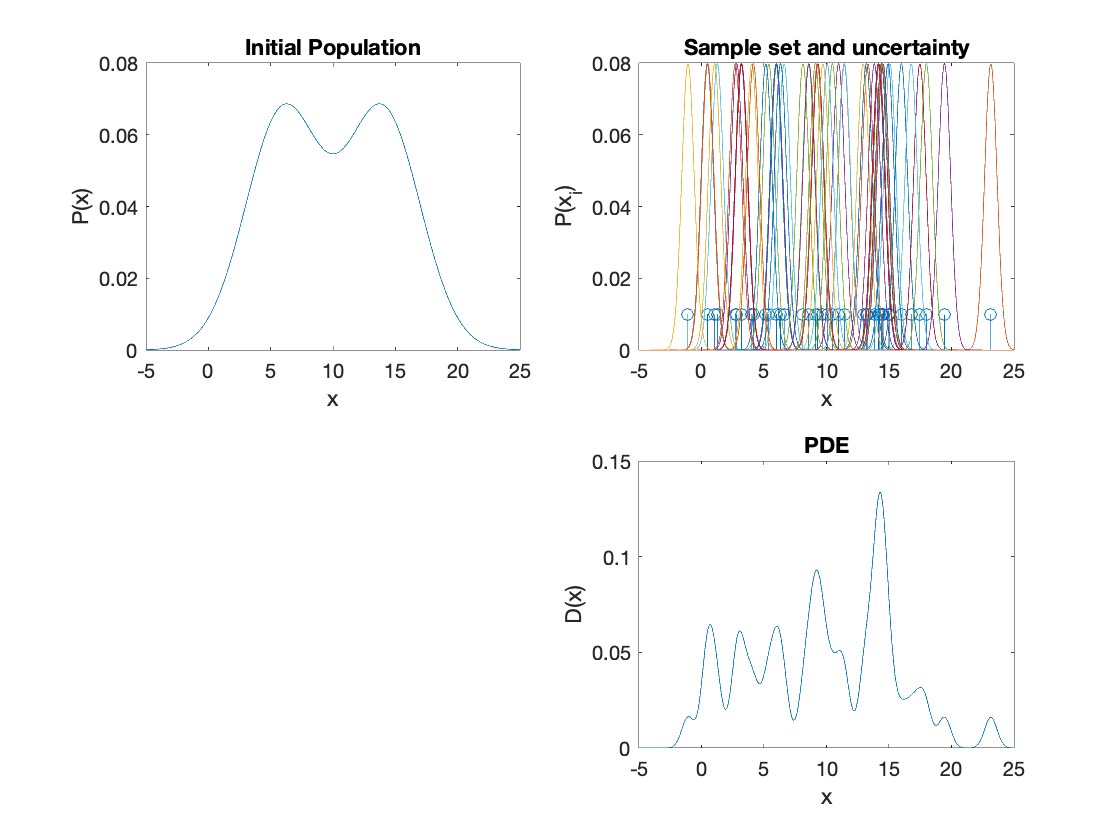

clear all;

% number of random samples
N = 50;

% bimodal parameters
mu = [6 14];
sigma = [3 3];

% sample uncertainty
sd = 0.5                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    ;

% create the distribution so you can see the original distribution that was
% sampled
x = [-5:0.01:25];
P = 0.5*gaussian(x,mu(1),sigma(1)) + 0.5*gaussian(x,mu(2),sigma(2));

% select 10 from this sample
xs = rejsample(x,P,N);

figure;
subplot(221);
plot(x,P);
xlabel('x');
ylabel('P(x)');
xlim([-5 25]);
title('Initial Population');

subplot(222);
hold on;
stem(xs,ones(size(xs))/(2*N));
% compute small Gaussian kernels
for i = 1:length(xs)
    K(i,:) = gaussian(x,xs(i),sd);
end
plot(x,K/10);
set(gca,'Box','on');
xlim([-5 25]);
xlabel('x');
ylabel('P(x_i)');
title('Sample set and uncertainty');

subplot(224);
hold on;
plot(x,sum(K,1)/N);
xlabel('x');
ylabel('D(x)');
title('PDE');
set(gca,'Box','on');
xlim([-5 25]);

### 4.4.2 Kernel Density Estimation (KDE)

The kernel density estimation method uses a model smoothing function called a kernel, $K(u)$, which always have the first and generally the second properties given below,

- Normalizes to unity, $\displaystyle 1 = \int_{-\infty}^{\infty} K(u) du$

- Symmetric: $K(-u) = K(u)$ for all $u$

A PDF can be estimated from the sum of kernels at the value of each observation, $x_i$, i.e.,


$$\hat{P}(x) = \frac{1}{Nh}\sum_{i=1}^N K\left( \frac{x - x_i}{h} \right)$$


where $N$ is the number of observations and $h$ is a scale factor for the kernel called the bandwidth.

Conceptually imagine the scenario below from a random sample of 10 points (bottom panel) from a bimodal distribution (top panel).  Create a Gaussian with a mean at each data point and some defined variance.  Then sum them up to produce a smooth model.  Note: although the example below uses 10 samples, it is generally not appropriate to perform KDE with such small samples because it can give the false impression of modes that may not exist if the true population.  How many samples do you need to adequately characterize your population with KDE?  It depends upon the complexity of the true population distribution.  You could try some synthetic tests using the Monte Carlo analysis as described in a previous section.  Or explore below by increasing the value of $N$ until the ideal and KDE distributions are sufficiently similar each time you run it.

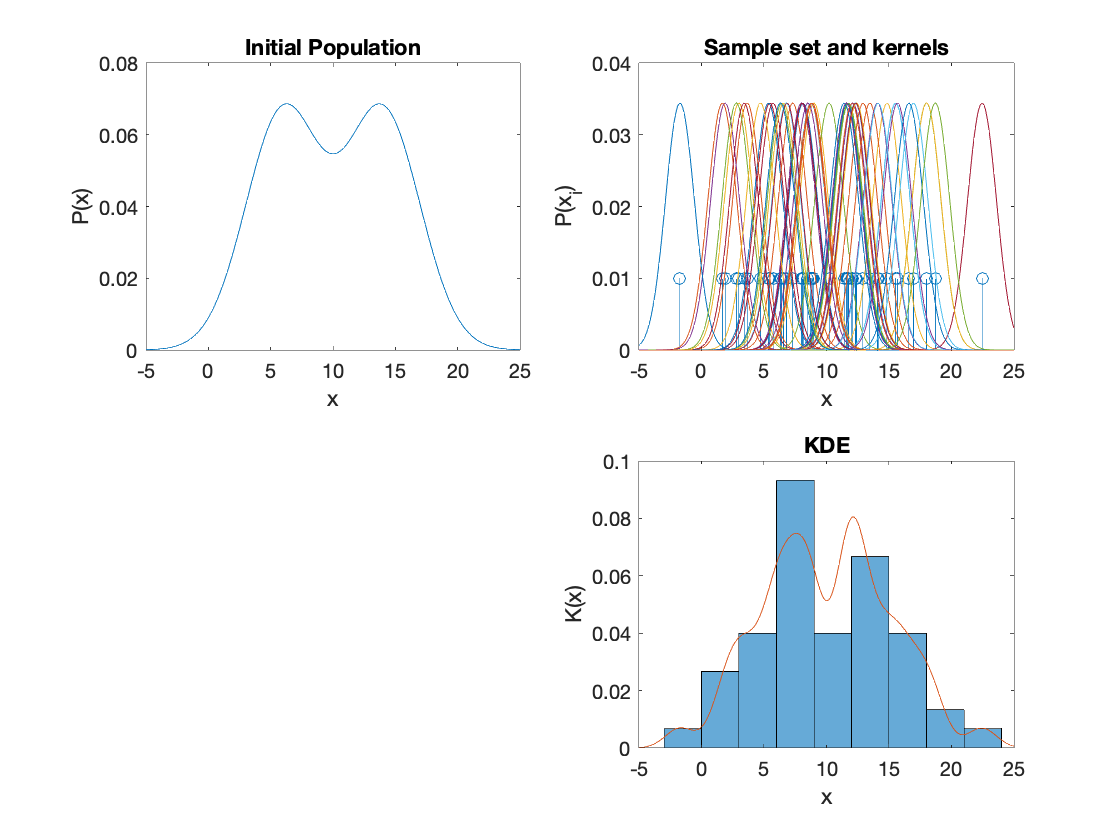

% kernel bandwidth
h = 1.06*sd/N^(-1/5);

% create the distribution so you can see the original distribution that was
% sampled
x = [-5:0.1:25];
P = 0.5*gaussian(x,mu(1),sigma(1)) + 0.5*gaussian(x,mu(2),sigma(2));

% select 10 from this sample
xs = rejsample(x,P,N);

figure;
subplot(221);
plot(x,P);
xlabel('x');
ylabel('P(x)');
title('Initial Population');
xlim([-5 25]);

subplot(222);
hold on;
stem(xs,ones(size(xs))/(2*N));

% compute Gaussian kernels
K = zeros([length(xs) length(x)]); % pre-allocate K to make the loop faster.
for i = 1:length(xs)
    K(i,:) = gaussian(x,xs(i),h);
end
plot(x,K/10);
xlabel('x');
ylabel('P(x_i)');
title('Sample set and kernels');
xlim([-5 25]);
set(gca,'Box','on');

subplot(224)
histogram(xs,'Normalization','pdf','BinMethod','sqrt');
hold on;
plot(x,sum(K,1)/N);
set(gca,'Box','on');
xlabel('x');
ylabel('K(x)');
title('KDE');
xlim([-5 25]);

Some common kernel functions include a Gaussian, with bandwidth equivalent to the variance,


$$K(u) = \frac{1}{\sqrt{2\pi}} \exp \left( -\frac{u^2}{2} \right)$$


Epanechnikov (a parabola),

$K(u) = \frac{3}{4} (1 - u^2)$ for $\left| u \right| \leq 1$

triangular,

$K(u) = (1 - |u| )$ for $\left| u \right| \leq 1$

and a boxcar,

$K(u) = \frac{1}{2}$ for $\left| u \right| \leq 1$.

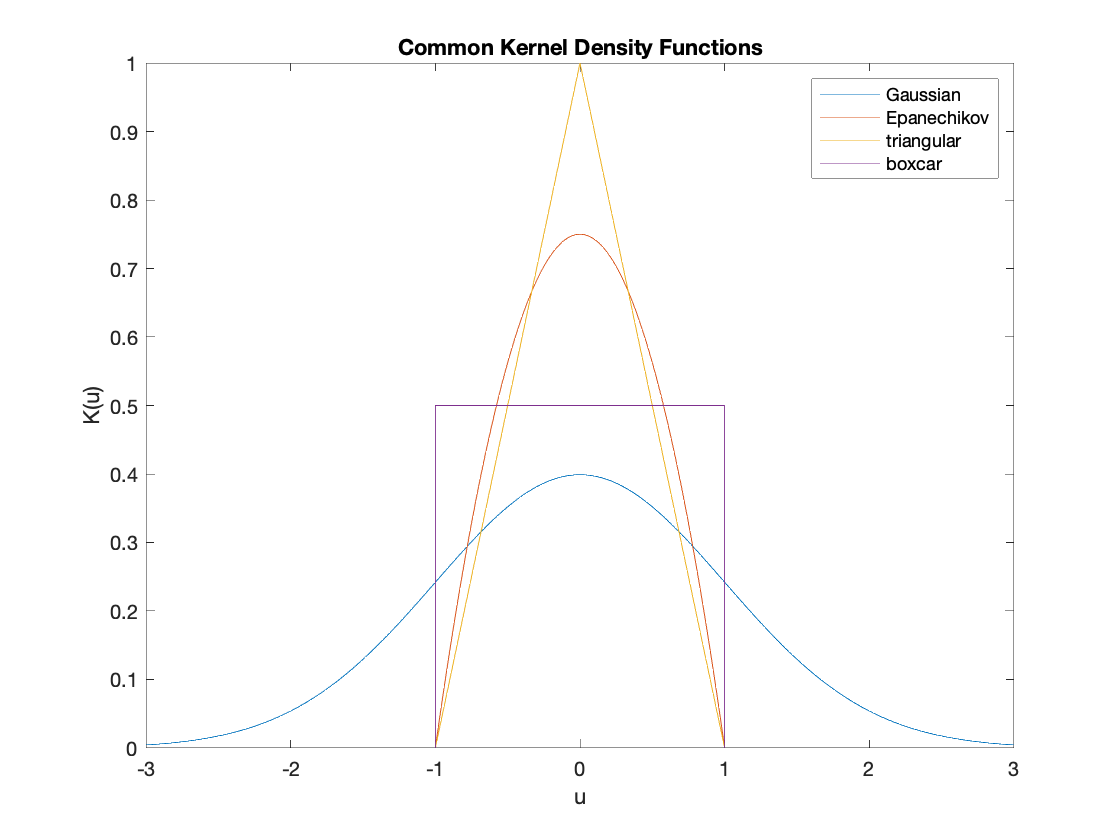

% examples of kernel density functions
clear all;

u = [-3:0.01:3];

figure;
hold on;
plot(u, (2*pi)^(-1/2)*exp(-u.^2/2));
ind = (abs(u) <= 1);
plot(u(ind), 3/4*(1 - u(ind).^2));
plot(u(ind), (1 - abs(u(ind))));
plot([-1 u(ind) 1], [0 0.5*ones(size(u(ind))) 0]);
legend('Gaussian','Epanechikov','triangular','boxcar');
xlabel('u');
ylabel('K(u)');
title('Common Kernel Density Functions');
set(gca,'Box','on')

There is only one last crucial thing to know...how to pick a bandwidth.  The optimal bandwidth for a Gaussian is $h \approx 1.06 s N^{-1/5}$, where $s$ is the sample standard deviation.  Note that the optimal bandwidth may be different for other distributions.  There are methods devised for more complex distributions which allow for adaptive bandwidth based on the density of samples.  However, adaptive methods are beyond the scope of this text.

KDE methods can also be used when the $X$ range is to censored, which means when values of $x$ cannot range from $(-\infty,\infty)$, but are constrained to only positive, $[0, \infty)$, e.g., log-normal distributions, or only negative, $(-\infty, 0]$, values.  Remember concentrations are constrained from [0,1].

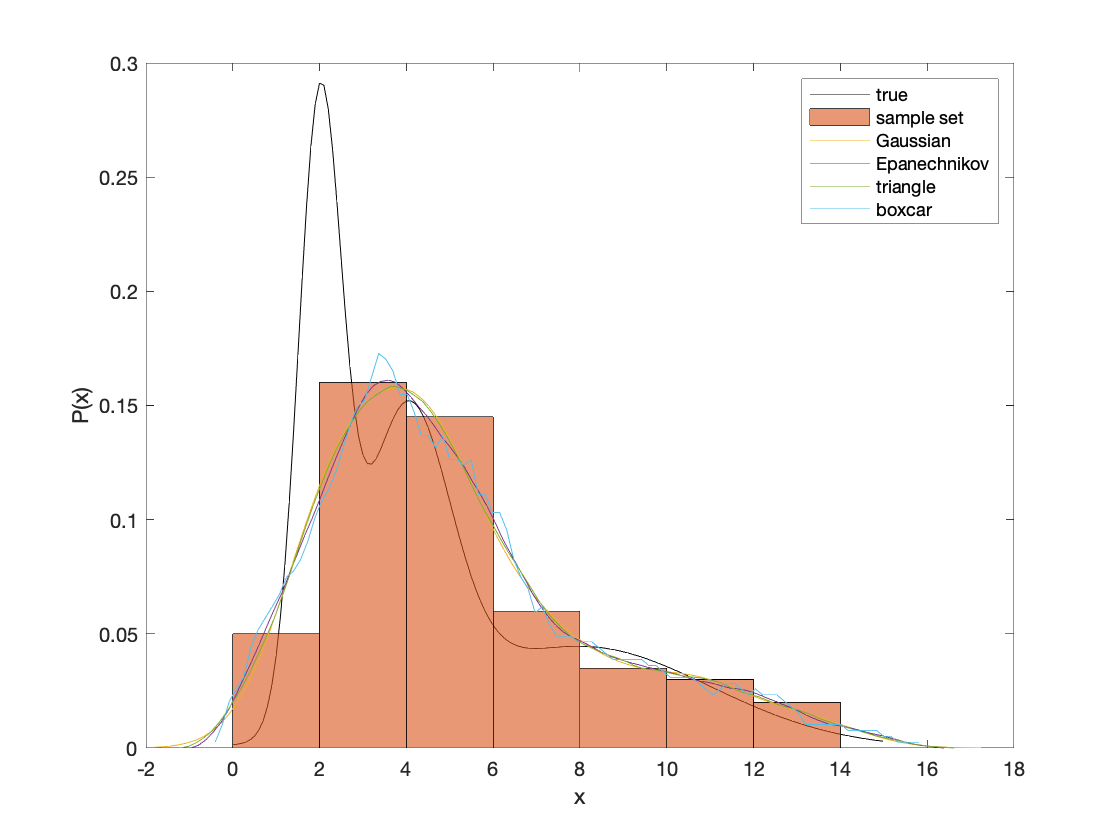

% Example of kernel density estimation
clear all;

% Let's return to our three Gaussian rejection sampled distribution for
% this example
% --- rejection sampling ---
% scale parameters for three normal distributions
mu = [2 4 8];
sigma = [0.5 1 3];

% create the combined distribution
dx = 0.1;
x = [0:dx:15];
% since we are creating a sum of three gaussians, start with a set of zero
% values for each x position.
P = zeros(size(x));
for i = 1:length(mu)
    % PN: I'm lazy and don't like to write the same equation every time I use
    % it so I wrote a gaussian function that will compute the gaussian
    % probabilities given a set of x values, the mean (mu) and standard
    % deviation (sigma).
    P = P + gaussian(x,mu(i),sigma(i));
end
% normalize probability so that it sums to 1
P = P/sum(P)/dx;

% number of random samples
N = 100;

% rejection sampling to produce random distribution
xs = rejsample(x,P,N);

% --- kernel density estimation ---
figure;
hold on;
plot(x,P,'k-');
histogram(xs,'Normalization','pdf');
ksdensity(xs,'Kernel','normal');
ksdensity(xs,'Kernel','epanechnikov');
ksdensity(xs,'Kernel','triangle');
ksdensity(xs,'Kernel','box');
legend('true','sample set','Gaussian','Epanechnikov','triangle','boxcar')
xlabel('x');
ylabel('P(x)');
set(gca,'Box','on');